# Find acoustic categories using UMAP on MPS from microphone

Playing around with all experimental dates manually checked so far as data gathered from DeafBats_CatCalls1

LocalDataDir = '/Users/elie/Documents/DeafBats/Data';
BaseDataDir = '/Volumes/server_home/users/JulieE/DeafSalineGroup151/';
BaseCodeDir = '/Users/elie/Documents/CODE/GitHub/';

Loading previous data

load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls2.mat'), 'CallType', 'BatID')
load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls.mat'),'MicAudioGood');
load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls.mat'), 'TmicAll','TmicAll7','MPSmicReduction4Clustering')
MicAudioGood01 = MicAudioGood;
MicAudioGood01(isnan(MicAudioGood01)) = 0;
MicAudioGood01 = logical(MicAudioGood01);

Get color vectors ready

% Get the color vector ready for call type
ColorCode = [get(groot, 'DefaultAxesColorOrder'); 0 1 1; 0.5 0.5 0.5; 1 0 0 ; 0 1 0 ; 0 0 1; 1 0 1; 0 0 0];
UCT = unique(CallType(~cellfun(@isempty, CallType)));
UCT = UCT([1:4 9 5:8 10:14])

UCT = 14×1 cell array
    {'BB' }
    {'Ba' }
    {'Bu' }
    {'Ch' }
    {'Pi' }
    {'LPi'}
    {'LT' }
    {'PB' }
    {'Pa' }
    {'Ra' }
    {'SB' }
    {'Sq' }
    {'Tr' }
    {'Un' }


UCTFull = UCT;
UCTFull{strcmp(UCT, 'Tr')} = 'Trill';
UCTFull{strcmp(UCT, 'Ba')} = 'Bark';
UCTFull{strcmp(UCT, 'Pi')} = 'Pitchy Call';
UCTFull{strcmp(UCT, 'LPi')} = 'Loud Pitchy Call';
UCTFull{strcmp(UCT, 'Bu')} = 'Low Buzz';
UCTFull{strcmp(UCT, 'Pa')} = 'Panting';
UCTFull{strcmp(UCT, 'LT')} = 'Low Tuck';
UCTFull{strcmp(UCT, 'Sq')} = 'Squeal';
UCTFull{strcmp(UCT, 'Ra')} = 'Rattle';
UCTFull{strcmp(UCT, 'Ch')} = 'Chuckles';
UCTFull{strcmp(UCT, 'BB')} = 'Bark Buzz';
UCTFull{strcmp(UCT, 'PB')} = 'Pitchy Call Buzz';
UCTFull{strcmp(UCT, 'SB')} = 'Squeal Buzz';
UCTFull{strcmp(UCT, 'Un')} = 'Unknown';
CCT = nan(length(CallType),3);
IndNoCall = cellfun(@isempty, CallType);
CallType(IndNoCall) = {'Un'};
for ct=1:length(UCT)
    CCT(contains(CallType,UCT(ct)),:) = repmat(ColorCode(ct,:),sum(contains(CallType,UCT(ct))),1);
end

% Get the color vector ready for BatName, Sex and Deafness
GGPath = dir('/Users/elie/Google Drive*');
Path2RecordingTable = fullfile(GGPath.folder, GGPath.name,'My Drive/JuvenileRecordings/DeafRecordingsNWAF155_Log.xlsx');
[~,~,RecTableData]=xlsread(Path2RecordingTable,2,'A1:k3','basic');
BatName = cell2mat(RecTableData(3,2:11));
BatSexDeaf = cell(size(BatName));
CSexDeaf =  nan(length(BatID),3);
SexDeaf =  cell(length(BatID),1);
Sex =  cell(length(BatID),1);
Deaf = cell(length(BatID),1);
CBat = nan(length(BatID),3);
UCBatName = nan(length(BatName),3);
for bat = 1:length(BatName)
    ColID = 1+ bat;
    CBat(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(bat,:),sum(contains(BatID,num2str(BatName(bat)))),1);
    UCBatName(bat,:) = ColorCode(bat,:);
    if strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(1,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Deaf Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(6,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Hearing Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(3,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Hearing Female';
    elseif strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(2,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Deaf Female';
    end
    
end
USexDeaf = {'Deaf Male' 'Hearing Male' 'Deaf Female' 'Hearing Female'};
UCSexDeaf = ColorCode([1 6 2 3], :);
BatName = BatName([1:7 10 8:9]);
BatSexDeaf = BatSexDeaf([1:7 10 8:9]);
UCBatName = UCBatName([1:7 10 8:9],:);
UCBatNameSexDeaf = ColorCode([2 2 2 3 3 3 1 1 6 6], :);
SexDeafMic = SexDeaf(MicAudioGood01);

#### Project all calls from all male individuals irrespective of deafening status

Using UMAP projection of all bats calculate an agglomerative hierarchical cluster tree Z for males only

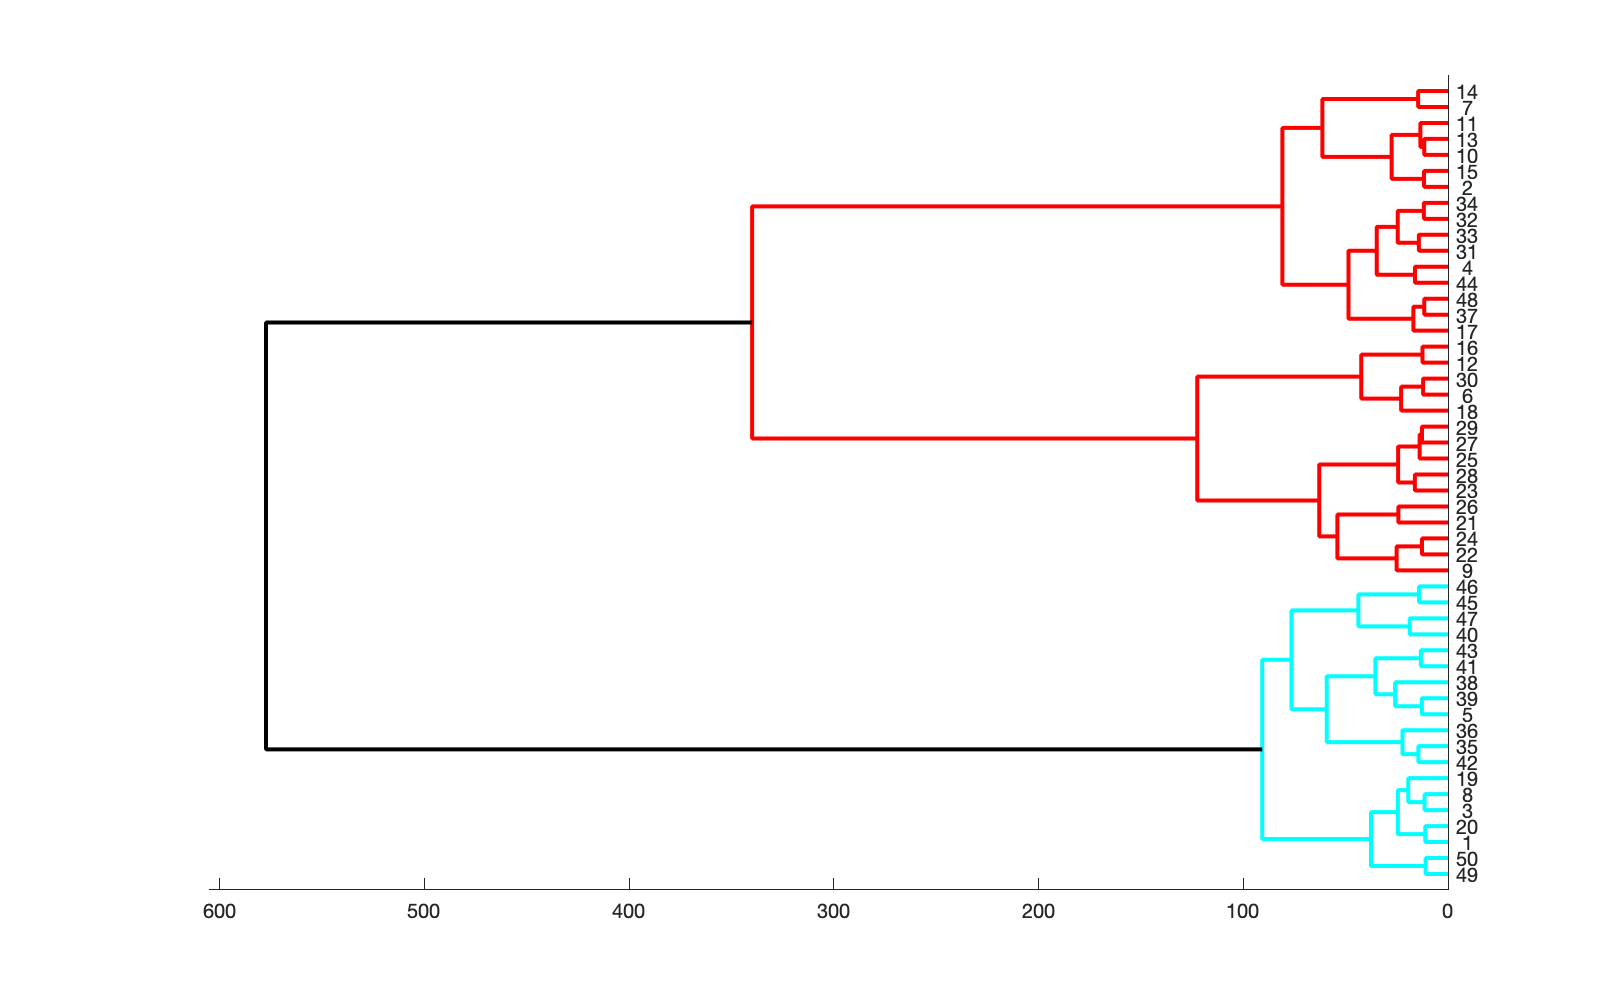

Z = linkage(MPSmicReduction4Clustering(contains(SexDeafMic, 'M'),:),'ward','euclidean');
% Cut the tree at first level and plot dendogram
[D1, T1, ~] = dendrogram(Z,50, 'ColorThreshold','Default','Orientation','left');
set(D1,'LineWidth',2)

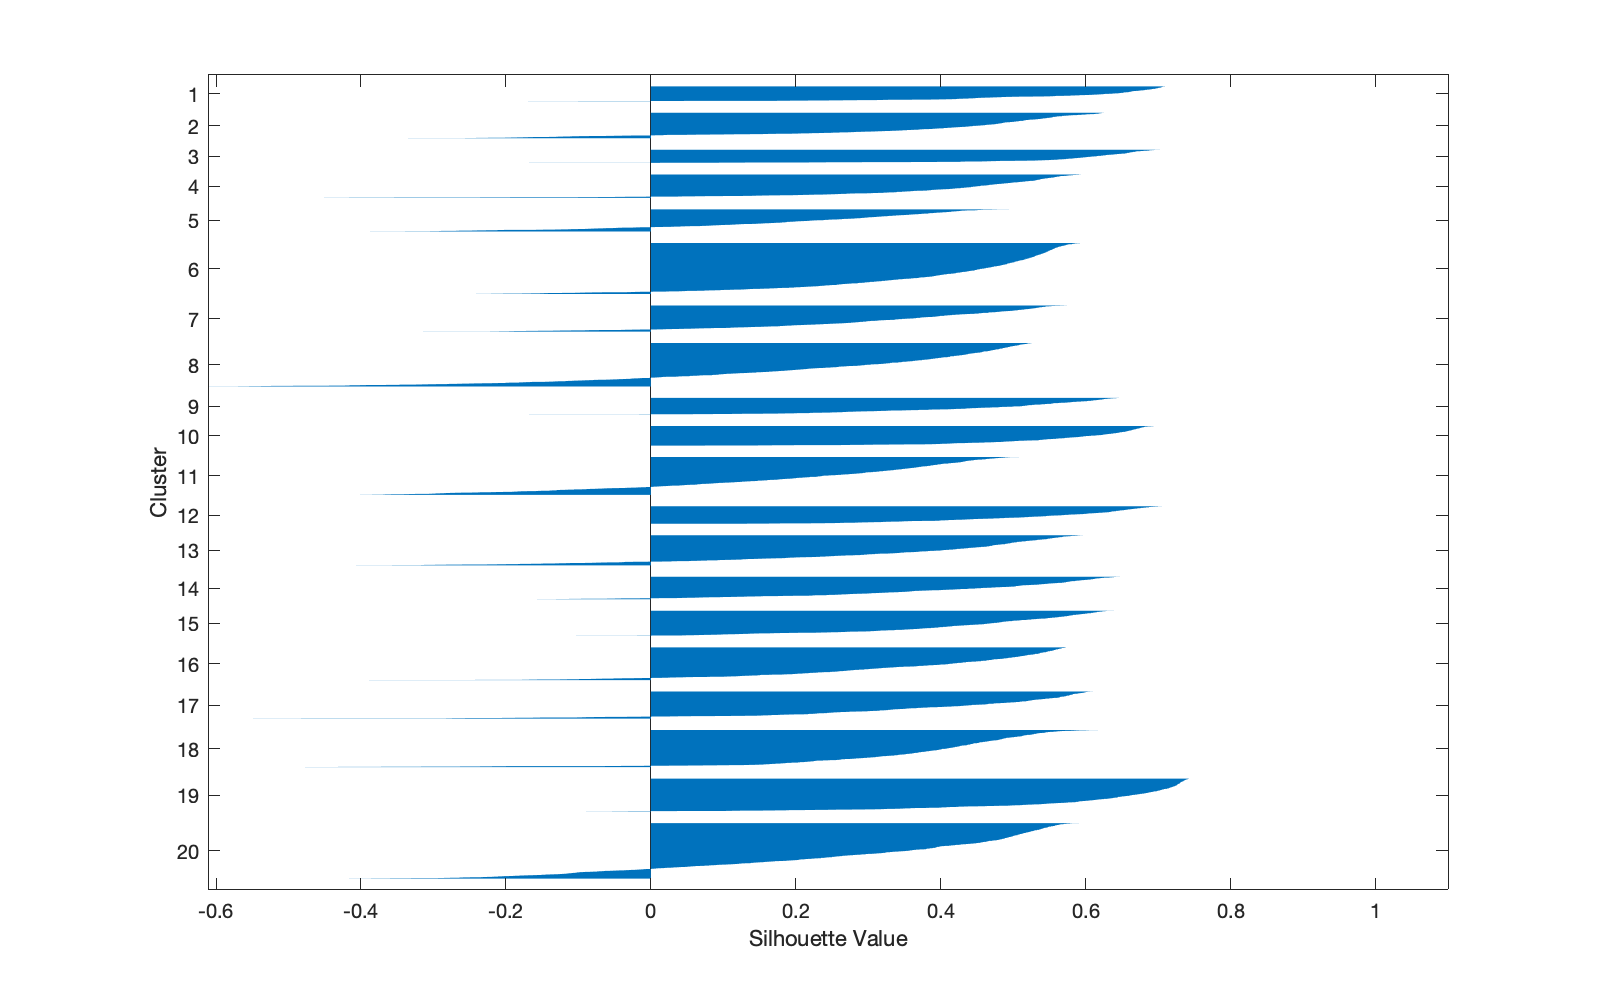

% Evaluate cluster quality accross various tree cut levels
ClustSize = 2:20;
MeanSilhouette = nan(size(ClustSize));
MedianSilhouette = nan(size(ClustSize));
PercLowSilhouette = nan(size(ClustSize));
LowSi = 0.3;
for cc=1:length(ClustSize)
    T = cluster(Z,'maxclust',ClustSize(cc));
    [Si,h] = silhouette(MPSmicReduction4Clustering(contains(SexDeafMic, 'M'),:),T, 'Euclidean');
    MeanSilhouette(cc) = mean(Si);
    MedianSilhouette(cc) = median(Si);
    PercLowSilhouette(cc) = sum(Si<LowSi)/length(Si);
end

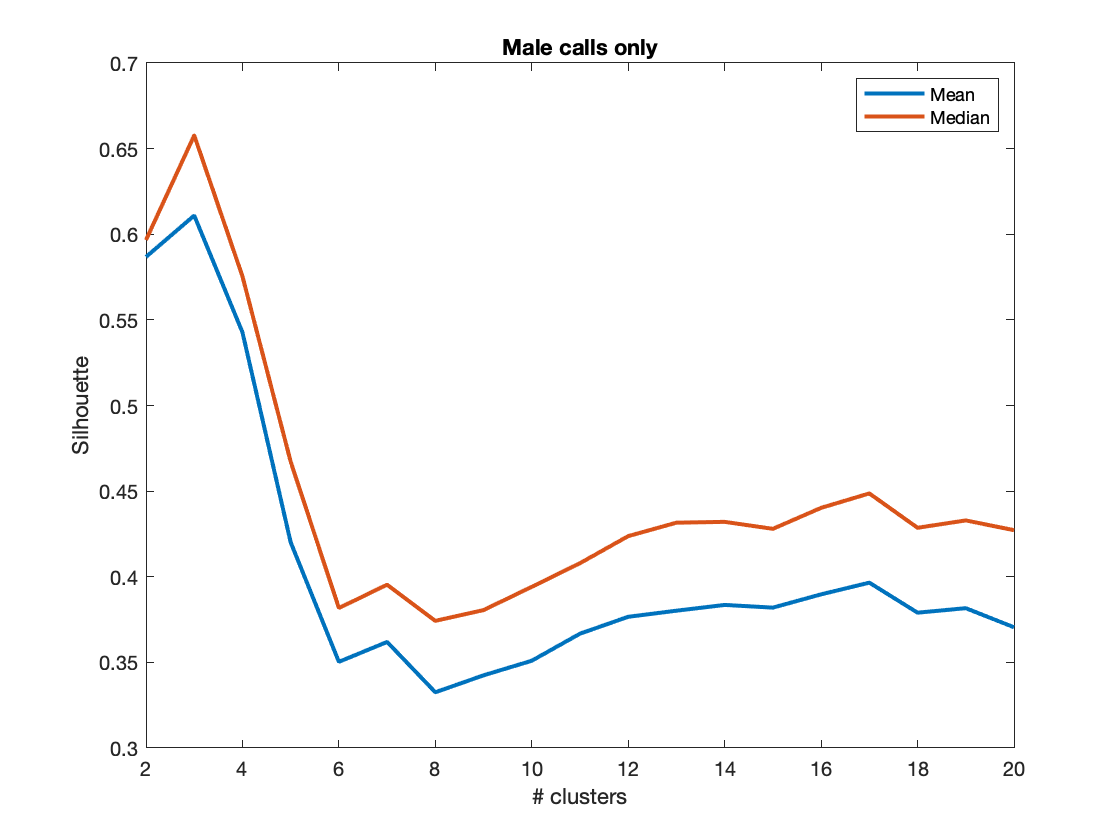

figure()
plot(2:20,MeanSilhouette, 'LineWidth',2)
hold on
plot(2:20,MedianSilhouette, 'LineWidth',2)
ylabel('Silhouette')
xlabel('# clusters')
legend('Mean', 'Median')
title('Male calls only')
hold off

eva = evalclusters(MPSmicReduction4Clustering(contains(SexDeafMic, 'M'),:), 'linkage','CalinskiHarabasz','KList',1:15)

eva =   CalinskiHarabaszEvaluation with properties:

    NumObservations: 14042
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 2.4469e+04 4.1613e+04 3.5753e+04 3.1570e+04 2.9250e+04 2.8264e+04 2.7097e+04 2.6668e+04 2.6773e+04 2.6965e+04 2.7097e+04 2.7136e+04 2.7408e+04 2.7476e+04]
           OptimalK: 3


eva = evalclusters(MPSmicReduction4Clustering(contains(SexDeafMic, 'M'),:), 'linkage','DaviesBouldin','KList',1:15)

eva =   DaviesBouldinEvaluation with properties:

    NumObservations: 14042
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 0.6137 0.5566 0.6883 0.9575 1.1227 1.1015 1.1360 1.0414 0.9782 0.8954 0.8862 0.8604 0.8554 0.8638]
           OptimalK: 3


eva = evalclusters(MPSmicReduction4Clustering(contains(SexDeafMic, 'M'),:), 'linkage','silhouette','KList',1:15)

eva =   SilhouetteEvaluation with properties:

    NumObservations: 14042
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 0.7680 0.8046 0.7473 0.5963 0.5003 0.5194 0.4713 0.4708 0.4788 0.5047 0.5186 0.5224 0.5321 0.5295]
           OptimalK: 3


Cut the Tree at 8 (NGroups) clusters and get the leaves labels (T)

NGroups = 8;
figure()
t=tiledlayout(1,2);
CTinCluster = nan(NGroups,length(UCT));
nexttile
[D, TmicMale, ~] = dendrogram(Z,NGroups, 'ColorThreshold','Default','Orientation','left');
set(D,'LineWidth',2)
CallTypeMicAudioGood = CallType(MicAudioGood01);
CallTypeMicAudioGoodM = CallTypeMicAudioGood(contains(SexDeafMic, 'M'))

CallTypeMicAudioGoodM = 14042×1 cell array
    {'Pi'}
    {'Pi'}
    {'Pi'}
    {'Pi'}
    {'Pi'}
    {'Ch'}
    {'Pi'}
    {'Un'}
    {'Pi'}
    {'Pi'}
    {'Un'}
    {'Pi'}
    {'Pi'}
    {'Pi'}
    {'Pi'}
    {'Pi'}
    {'Pi'}
    {'Ba'}
    {'Pi'}
    {'Pi'}
    {'Pi'}
    {'Pi'}
    {'Pi'}
    {'Pi'}
    {'Pi'}
    {'Pi'}
    {'Pi'}
    {'Pi'}
    {'Pi'}
    {'Pi'}


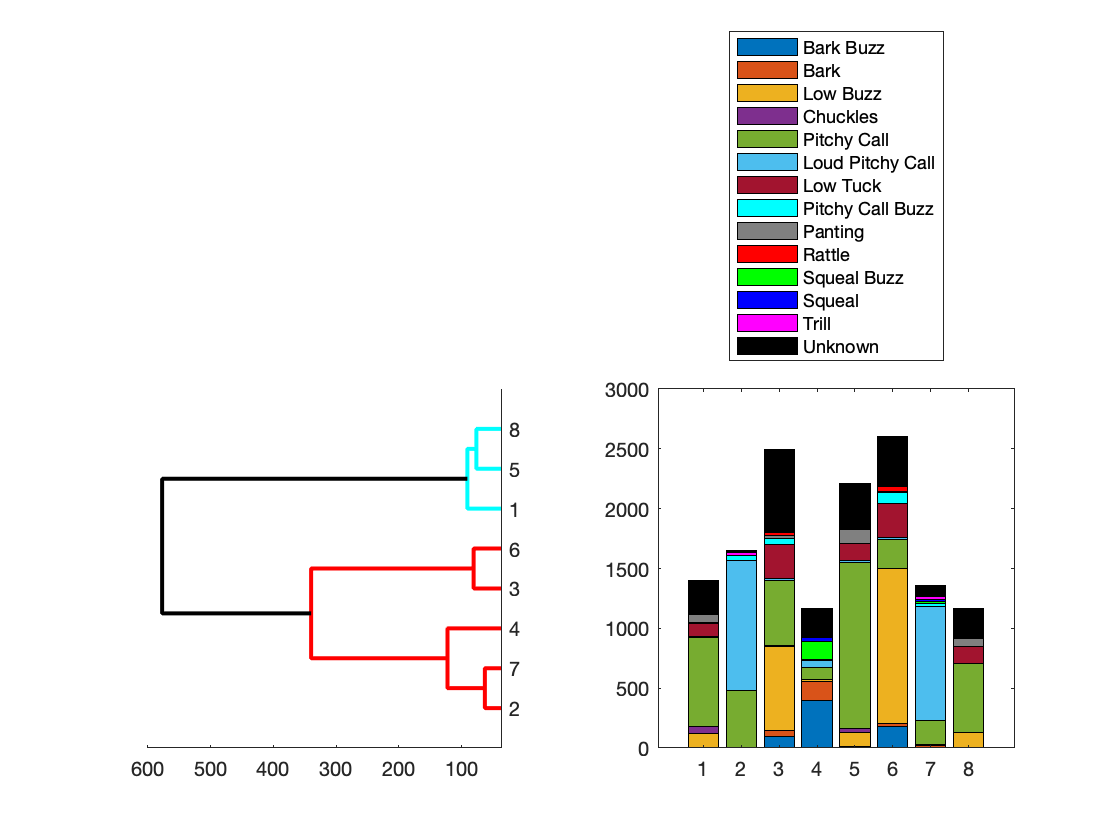

for cc=1:NGroups
    for ct=1:length(UCT)
        CTinCluster(cc,ct) = sum(strcmp(CallTypeMicAudioGoodM(TmicMale==cc), UCT{ct}));
    end
end
nexttile
B = bar(CTinCluster, 'stacked');
B(8).FaceColor = ColorCode(8,:);
B(9).FaceColor = ColorCode(9,:);
B(10).FaceColor = ColorCode(10,:);
B(11).FaceColor = ColorCode(11,:);
B(12).FaceColor = ColorCode(12,:);
B(13).FaceColor = ColorCode(13,:);
B(14).FaceColor = ColorCode(14,:);
legend(UCTFull, 'Location', 'northoutside')

Project the vocalizations in 3D UMAP space and colorcode according to acoustic hierarchical agglomerative clusters.

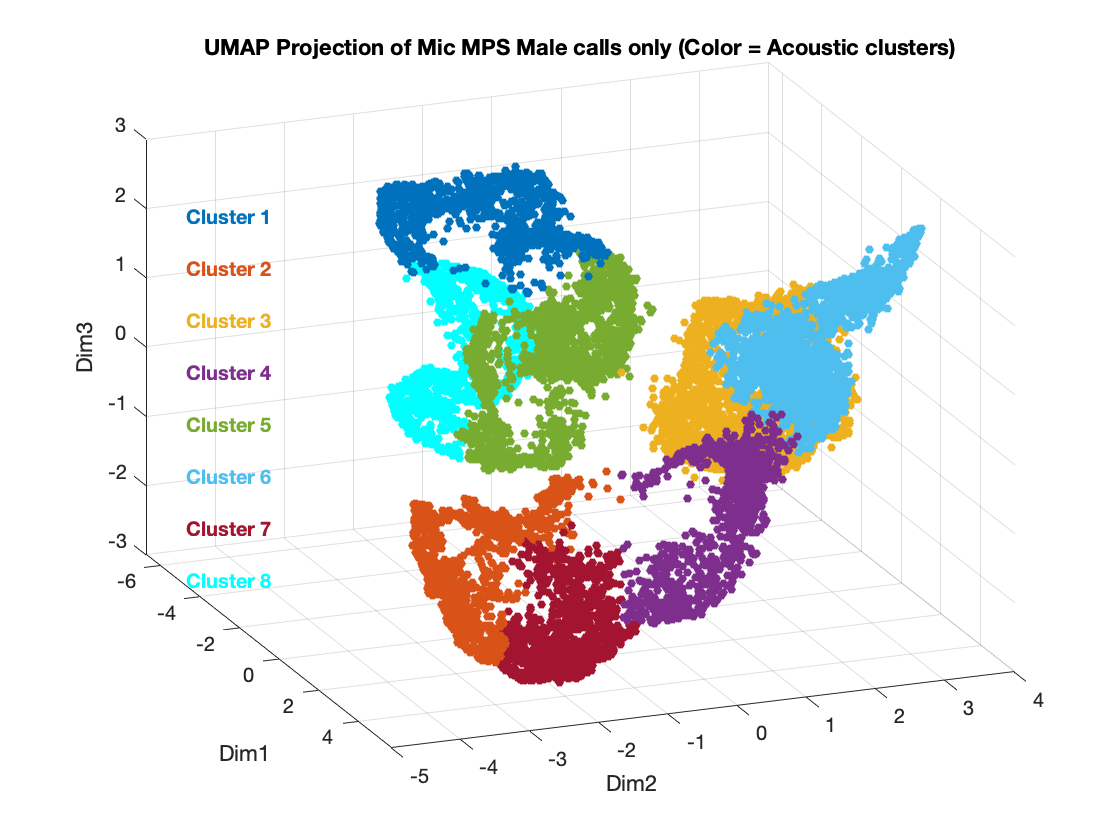

%%
figure()
scatter3(MPSmicReduction4Clustering(contains(SexDeafMic, 'M'),1), MPSmicReduction4Clustering(contains(SexDeafMic, 'M'),2),MPSmicReduction4Clustering(contains(SexDeafMic, 'M'),3),20,ColorCode(TmicMale,:,:),'filled')
xlabel('Dim1')
ylabel('Dim2')
zlabel('Dim3')
ZLim = get(gca, 'ZLim');
title('UMAP Projection of Mic MPS Male calls only (Color = Acoustic clusters)')
for gg=1:NGroups
    text(-5,-4.9, ZLim(2)-diff(ZLim)*gg/NGroups, sprintf('Cluster %d',gg), 'Color',ColorCode(gg,:), 'FontWeight','bold' )
end
view([68.50 26.52])

#### Project all calls from all hearing male individuals

Using UMAP projection of all bats calculate an agglomerative hierarchical cluster tree Z for males only

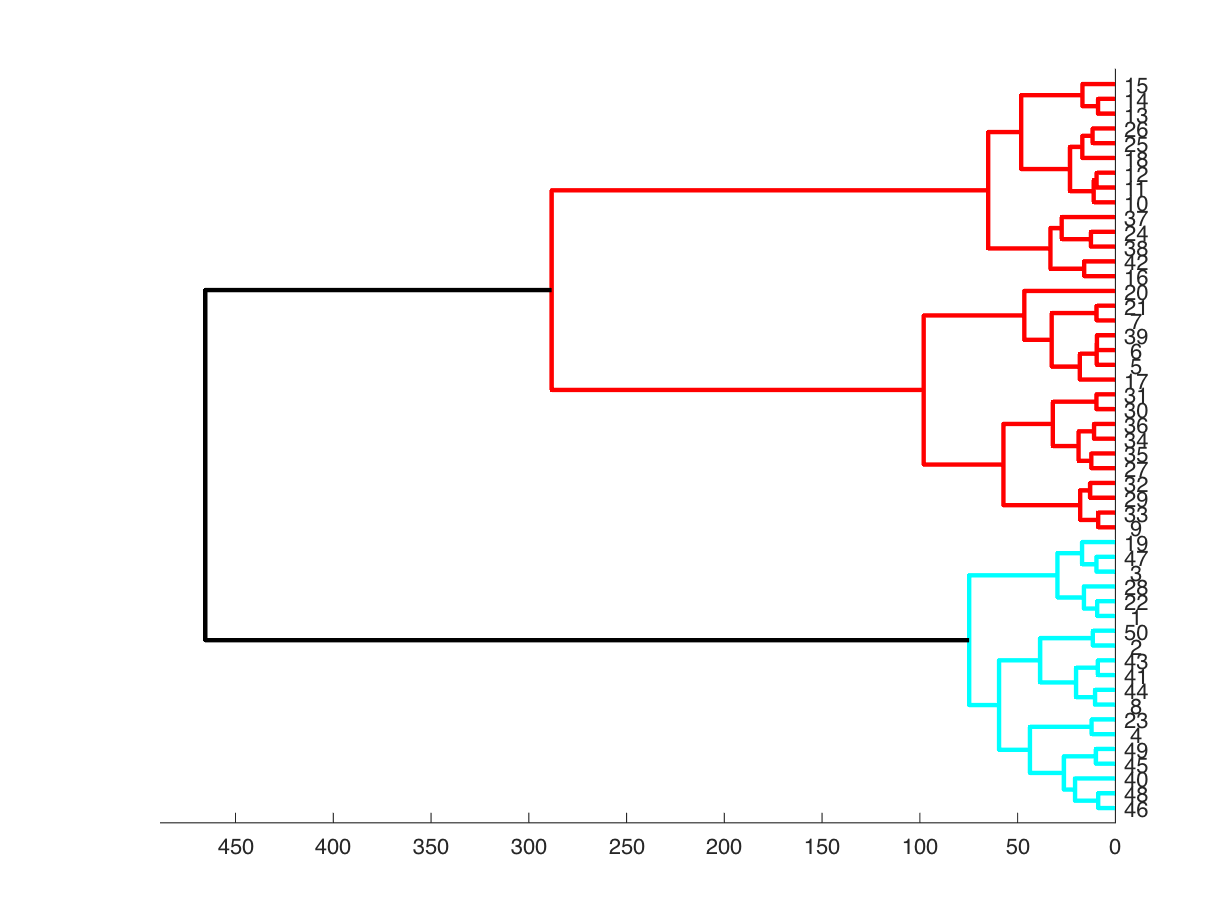

Z = linkage(MPSmicReduction4Clustering(contains(SexDeafMic, 'HM'),:),'ward','euclidean');
% Cut the tree at first level and plot dendogram
[D1, T1, ~] = dendrogram(Z,50, 'ColorThreshold','Default','Orientation','left');
set(D1,'LineWidth',2)

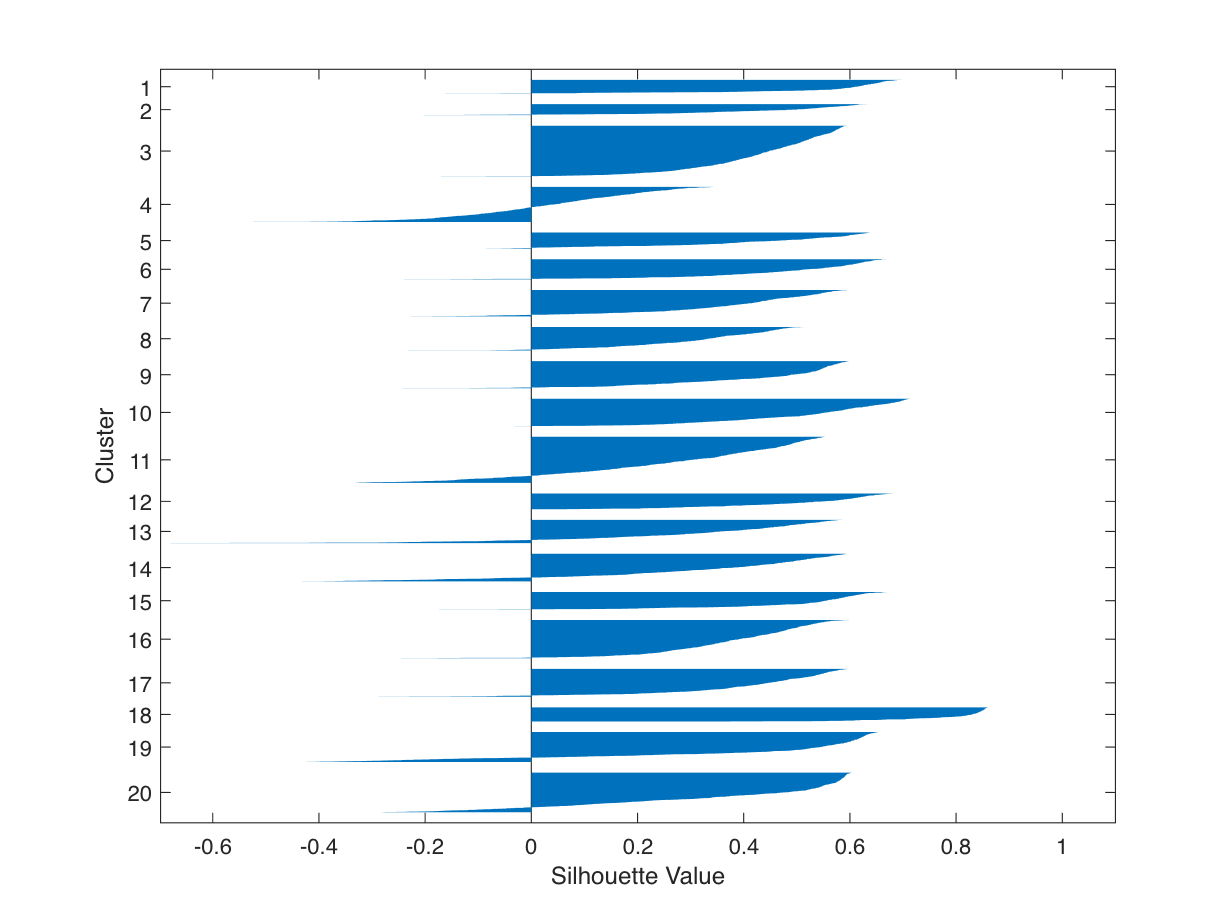

% Evaluate cluster quality accross various tree cut levels
ClustSize = 2:20;
MeanSilhouette = nan(size(ClustSize));
MedianSilhouette = nan(size(ClustSize));
PercLowSilhouette = nan(size(ClustSize));
LowSi = 0.3;
for cc=1:length(ClustSize)
    T = cluster(Z,'maxclust',ClustSize(cc));
    [Si,h] = silhouette(MPSmicReduction4Clustering(contains(SexDeafMic, 'HM'),:),T, 'Euclidean');
    MeanSilhouette(cc) = mean(Si);
    MedianSilhouette(cc) = median(Si);
    PercLowSilhouette(cc) = sum(Si<LowSi)/length(Si);
end

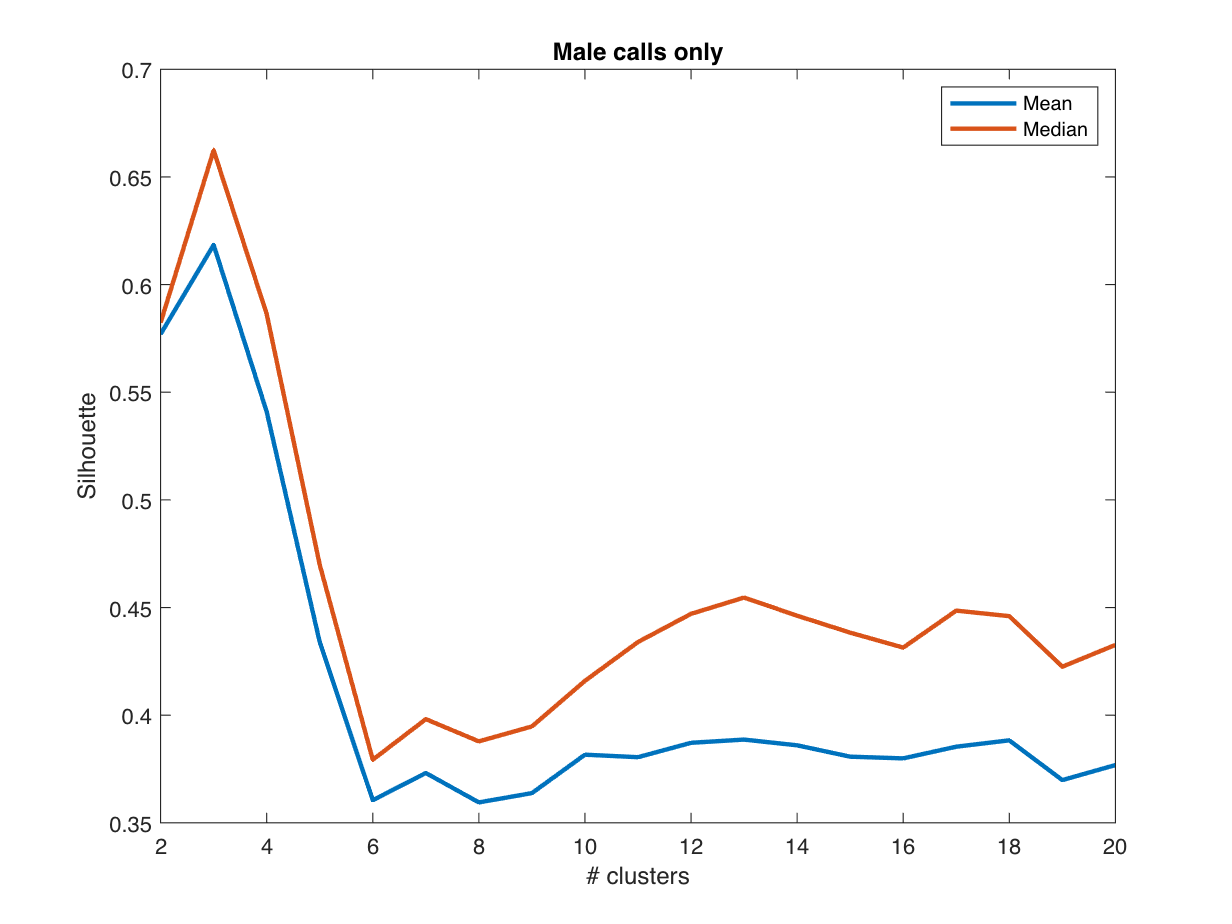

figure()
plot(2:20,MeanSilhouette, 'LineWidth',2)
hold on
plot(2:20,MedianSilhouette, 'LineWidth',2)
ylabel('Silhouette')
xlabel('# clusters')
legend('Mean', 'Median')
title('Male calls only')
hold off

eva = evalclusters(MPSmicReduction4Clustering(contains(SexDeafMic, 'HM'),:), 'linkage','CalinskiHarabasz','KList',1:15)

eva =   CalinskiHarabaszEvaluation with properties:

    NumObservations: 9396
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 1.5369e+04 2.8558e+04 2.4406e+04 2.1691e+04 2.0077e+04 1.9191e+04 1.8978e+04 1.8597e+04 1.8587e+04 1.8753e+04 1.8796e+04 1.8642e+04 1.8672e+04 1.8880e+04]
           OptimalK: 3


eva = evalclusters(MPSmicReduction4Clustering(contains(SexDeafMic, 'HM'),:), 'linkage','DaviesBouldin','KList',1:15)

eva =   DaviesBouldinEvaluation with properties:

    NumObservations: 9396
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 0.6238 0.5396 0.7876 1.0050 1.1211 1.1153 1.0609 0.9865 0.9138 0.8761 0.8172 0.8397 0.8342 0.8369]
           OptimalK: 3


eva = evalclusters(MPSmicReduction4Clustering(contains(SexDeafMic, 'HM'),:), 'linkage','silhouette','KList',1:15)

eva =   SilhouetteEvaluation with properties:

    NumObservations: 9396
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 0.7519 0.8108 0.7385 0.6090 0.5101 0.5261 0.5027 0.5025 0.5233 0.5129 0.5248 0.5251 0.5254 0.5209]
           OptimalK: 3


Cut the Tree at 6 (NGroups) clusters and get the leaves labels (T)

NGroups = 6;
figure()
t=tiledlayout(1,2);
CTinCluster = nan(NGroups,length(UCT));
nexttile
[D, TmicHMale, ~] = dendrogram(Z,NGroups, 'ColorThreshold','Default','Orientation','left');
set(D,'LineWidth',2)
CallTypeMicAudioGood = CallType(MicAudioGood01);
CallTypeMicAudioGoodM = CallTypeMicAudioGood(contains(SexDeafMic, 'HM'))

CallTypeMicAudioGoodM = 9396×1 cell array
    {'Pi'}
    {'Pi'}
    {'Pi'}
    {'Pi'}
    {'Pi'}
    {'Ch'}
    {'Pi'}
    {'Un'}
    {'Pi'}
    {'Pi'}
    {'Un'}
    {'Pi'}
    {'Pi'}
    {'Pi'}
    {'Pi'}
    {'Pi'}
    {'Ba'}
    {'Pi'}
    {'Pi'}
    {'Pi'}
    {'Pi'}
    {'Pi'}
    {'Pi'}
    {'Pi'}
    {'Pi'}
    {'Pi'}
    {'Pi'}
    {'Pi'}
    {'Pi'}
    {'Pi'}


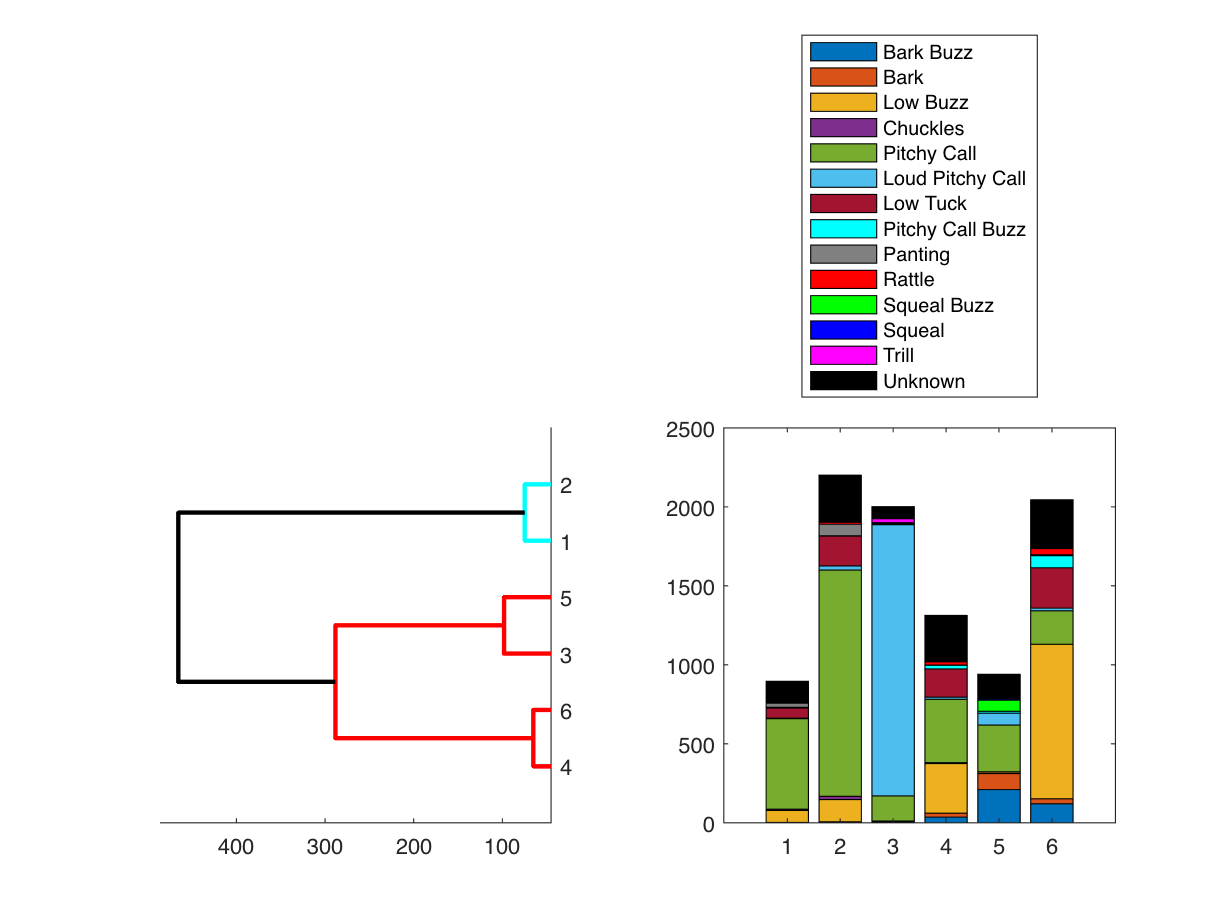

for cc=1:NGroups
    for ct=1:length(UCT)
        CTinCluster(cc,ct) = sum(strcmp(CallTypeMicAudioGoodM(TmicHMale==cc), UCT{ct}));
    end
end
nexttile
B = bar(CTinCluster, 'stacked');
B(8).FaceColor = ColorCode(8,:);
B(9).FaceColor = ColorCode(9,:);
B(10).FaceColor = ColorCode(10,:);
B(11).FaceColor = ColorCode(11,:);
B(12).FaceColor = ColorCode(12,:);
B(13).FaceColor = ColorCode(13,:);
B(14).FaceColor = ColorCode(14,:);
legend(UCTFull, 'Location', 'northoutside')

Project the vocalizations in 3D UMAP space and colorcode according to acoustic hierarchical agglomerative clusters.

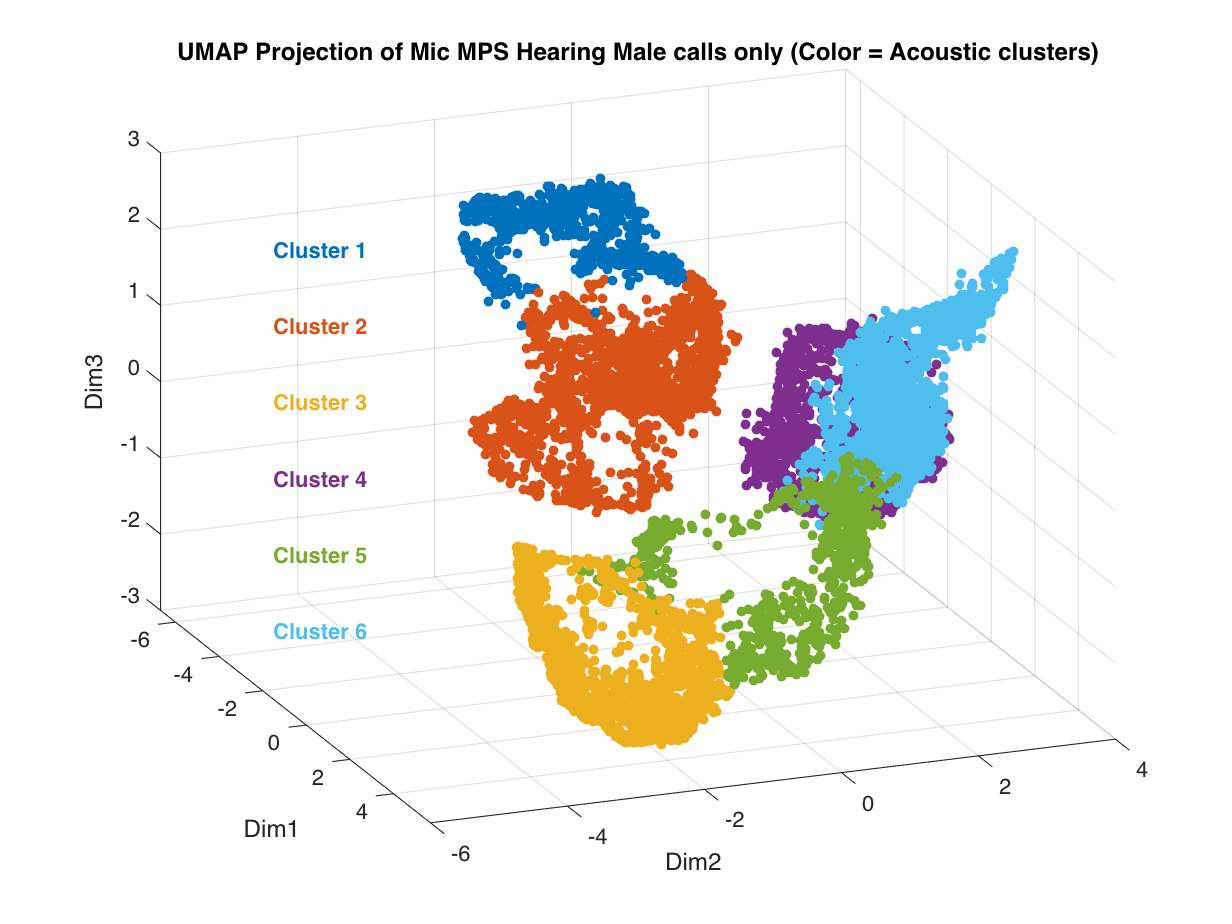

%%
figure()
scatter3(MPSmicReduction4Clustering(contains(SexDeafMic, 'HM'),1), MPSmicReduction4Clustering(contains(SexDeafMic, 'HM'),2),MPSmicReduction4Clustering(contains(SexDeafMic, 'HM'),3),20,ColorCode(TmicHMale,:,:),'filled')
xlabel('Dim1')
ylabel('Dim2')
zlabel('Dim3')
ZLim = get(gca, 'ZLim');
title('UMAP Projection of Mic MPS Hearing Male calls only (Color = Acoustic clusters)')
for gg=1:NGroups
    text(-5,-4.9, ZLim(2)-diff(ZLim)*gg/NGroups, sprintf('Cluster %d',gg), 'Color',ColorCode(gg,:), 'FontWeight','bold' )
end
view([68.50 26.52])

#### Project all calls from all deaf male individuals

Using UMAP projection of all bats calculate an agglomerative hierarchical cluster tree Z for males only

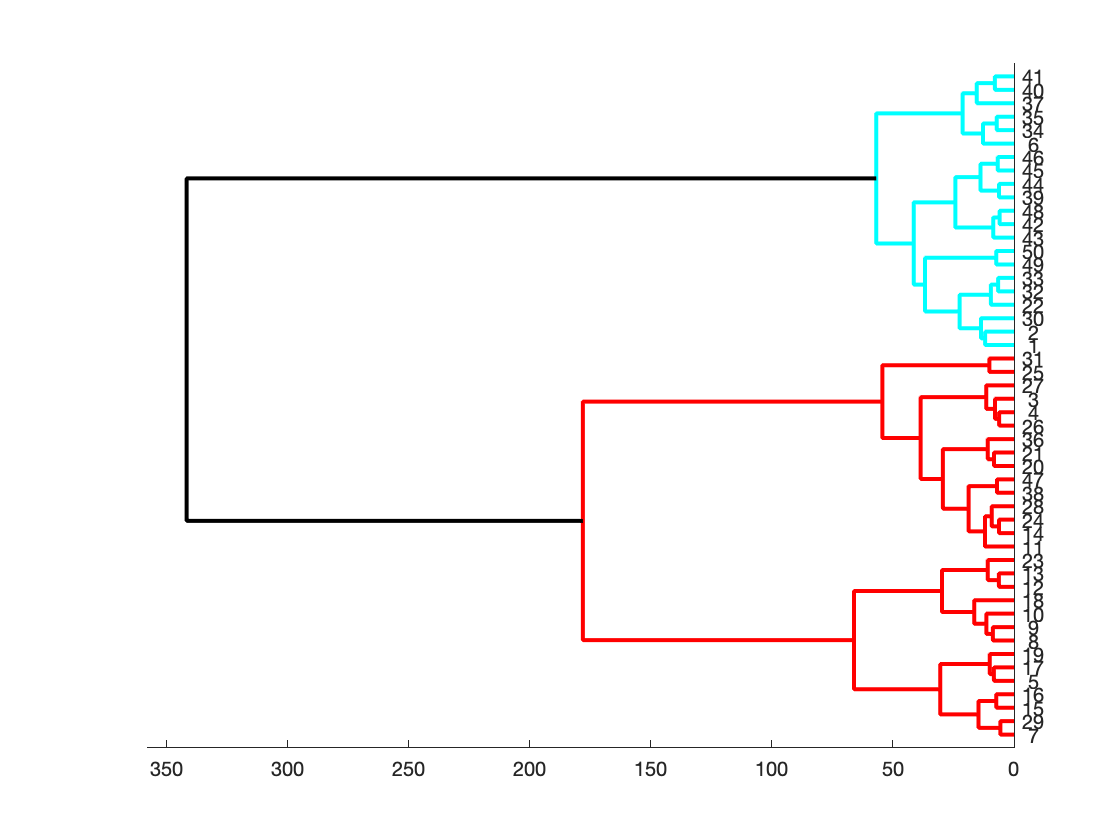

Z = linkage(MPSmicReduction4Clustering(contains(SexDeafMic, 'DM'),:),'ward','euclidean');
% Cut the tree at first level and plot dendogram
[D1, T1, ~] = dendrogram(Z,50, 'ColorThreshold','Default','Orientation','left');
set(D1,'LineWidth',2)

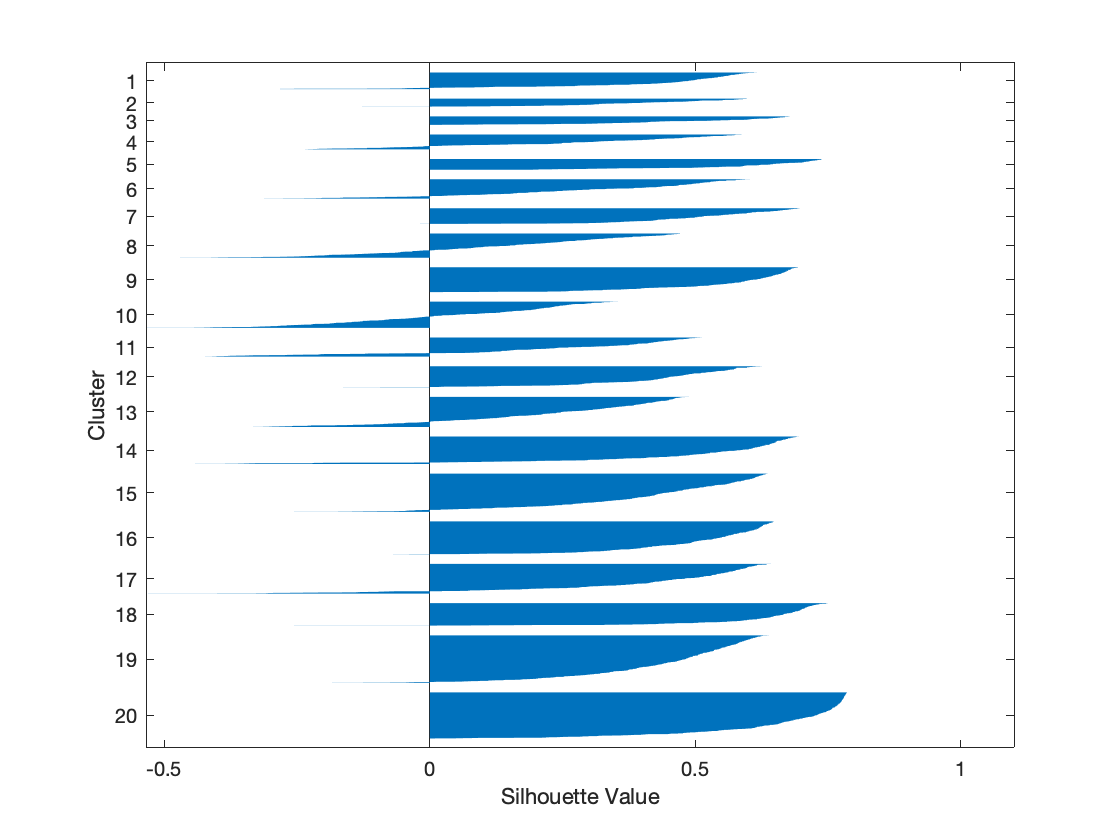

% Evaluate cluster quality accross various tree cut levels
ClustSize = 2:20;
MeanSilhouette = nan(size(ClustSize));
MedianSilhouette = nan(size(ClustSize));
PercLowSilhouette = nan(size(ClustSize));
LowSi = 0.3;
for cc=1:length(ClustSize)
    T = cluster(Z,'maxclust',ClustSize(cc));
    [Si,h] = silhouette(MPSmicReduction4Clustering(contains(SexDeafMic, 'DM'),:),T, 'Euclidean');
    MeanSilhouette(cc) = mean(Si);
    MedianSilhouette(cc) = median(Si);
    PercLowSilhouette(cc) = sum(Si<LowSi)/length(Si);
end

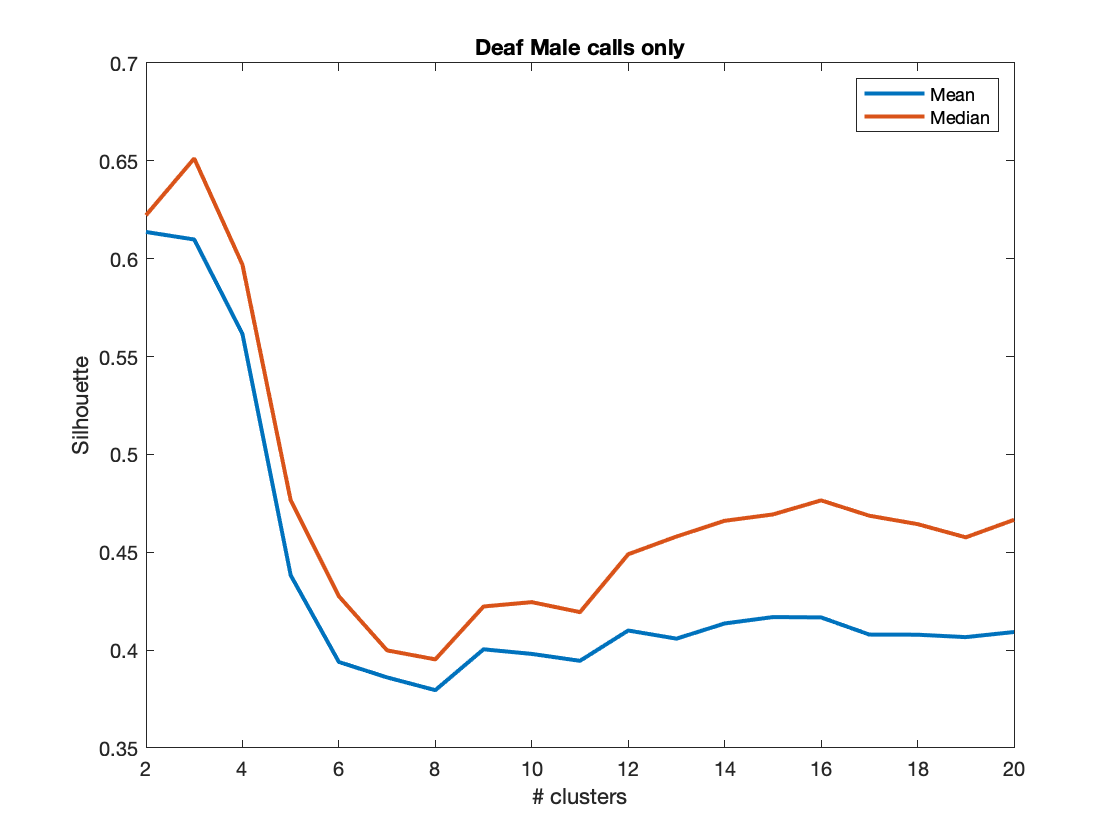

figure()
plot(2:20,MeanSilhouette, 'LineWidth',2)
hold on
plot(2:20,MedianSilhouette, 'LineWidth',2)
ylabel('Silhouette')
xlabel('# clusters')
legend('Mean', 'Median')
title('Deaf Male calls only')
hold off

eva = evalclusters(MPSmicReduction4Clustering(contains(SexDeafMic, 'DM'),:), 'linkage','CalinskiHarabasz','KList',1:15)

eva =   CalinskiHarabaszEvaluation with properties:

    NumObservations: 4646
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 9.6174e+03 1.3966e+04 1.1645e+04 1.0607e+04 1.0454e+04 1.0021e+04 9.8470e+03 9.9125e+03 9.8110e+03 9.8894e+03 1.0166e+04 1.0219e+04 1.0282e+04 1.0378e+04]
           OptimalK: 3


eva = evalclusters(MPSmicReduction4Clustering(contains(SexDeafMic, 'DM'),:), 'linkage','DaviesBouldin','KList',1:15)

eva =   DaviesBouldinEvaluation with properties:

    NumObservations: 4646
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 0.5780 0.5831 0.6991 0.9190 0.9010 0.9744 1.0117 0.9175 0.8999 0.9013 0.9110 0.9041 0.9196 0.9329]
           OptimalK: 2


eva = evalclusters(MPSmicReduction4Clustering(contains(SexDeafMic, 'DM'),:), 'linkage','silhouette','KList',1:15)

eva =   SilhouetteEvaluation with properties:

    NumObservations: 4646
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 0.8020 0.8049 0.7618 0.6140 0.5371 0.5253 0.5135 0.5387 0.5413 0.5336 0.5573 0.5455 0.5590 0.5631]
           OptimalK: 3


Cut the Tree at 8 (NGroups) clusters and get the leaves labels (T)

NGroups = 8;
figure()
t=tiledlayout(1,2);
CTinCluster = nan(NGroups,length(UCT));
nexttile
[D, TmicDMale, ~] = dendrogram(Z,NGroups, 'ColorThreshold','Default','Orientation','left');
set(D,'LineWidth',2)
CallTypeMicAudioGood = CallType(MicAudioGood01);
CallTypeMicAudioGoodM = CallTypeMicAudioGood(contains(SexDeafMic, 'DM'))

CallTypeMicAudioGoodM = 4646×1 cell array
    {'Pi'}
    {'Pi'}
    {'Pi'}
    {'Pi'}
    {'Pi'}
    {'Pi'}
    {'LT'}
    {'LT'}
    {'LT'}
    {'LT'}
    {'LT'}
    {'LT'}
    {'Bu'}
    {'Bu'}
    {'LT'}
    {'Bu'}
    {'LT'}
    {'Bu'}
    {'Bu'}
    {'LT'}
    {'Pi'}
    {'Pi'}
    {'Pi'}
    {'Pa'}
    {'Ch'}
    {'Ch'}
    {'Ch'}
    {'Ch'}
    {'Pi'}
    {'Pi'}


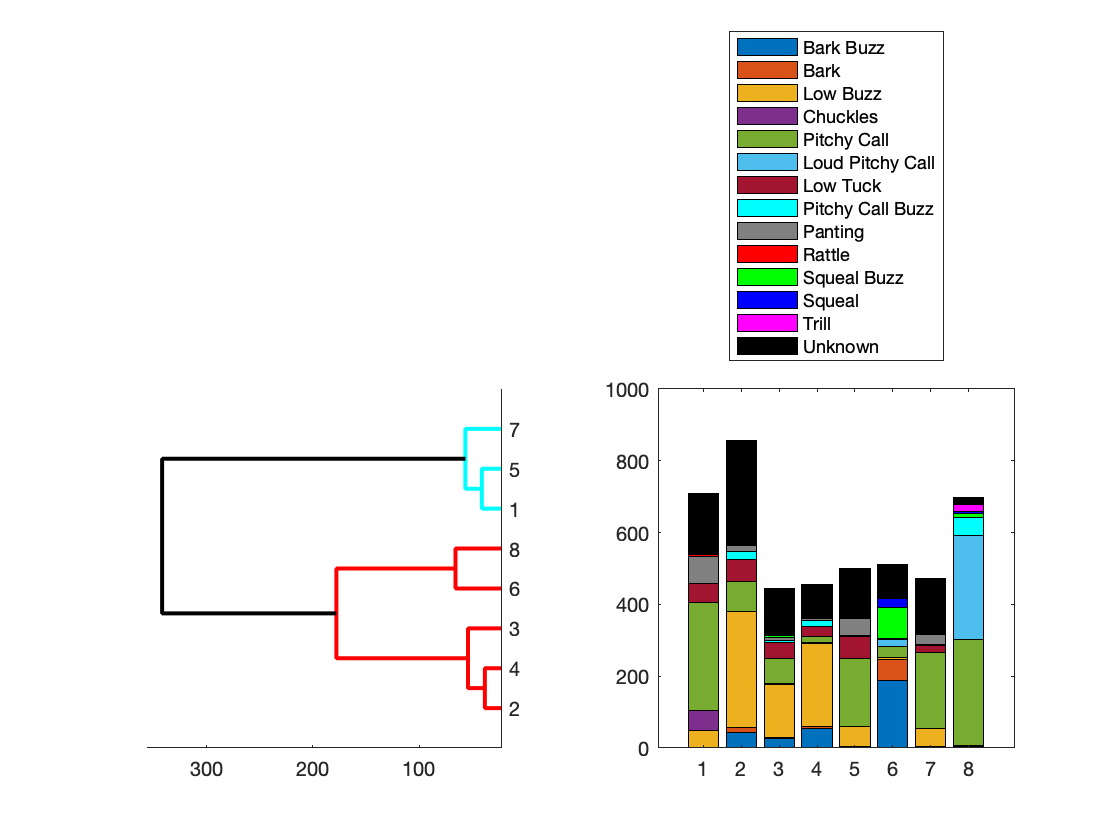

for cc=1:NGroups
    for ct=1:length(UCT)
        CTinCluster(cc,ct) = sum(strcmp(CallTypeMicAudioGoodM(TmicDMale==cc), UCT{ct}));
    end
end
nexttile
B = bar(CTinCluster, 'stacked');
B(8).FaceColor = ColorCode(8,:);
B(9).FaceColor = ColorCode(9,:);
B(10).FaceColor = ColorCode(10,:);
B(11).FaceColor = ColorCode(11,:);
B(12).FaceColor = ColorCode(12,:);
B(13).FaceColor = ColorCode(13,:);
B(14).FaceColor = ColorCode(14,:);
legend(UCTFull, 'Location', 'northoutside')

Project the vocalizations in 3D UMAP space and colorcode according to acoustic hierarchical agglomerative clusters.

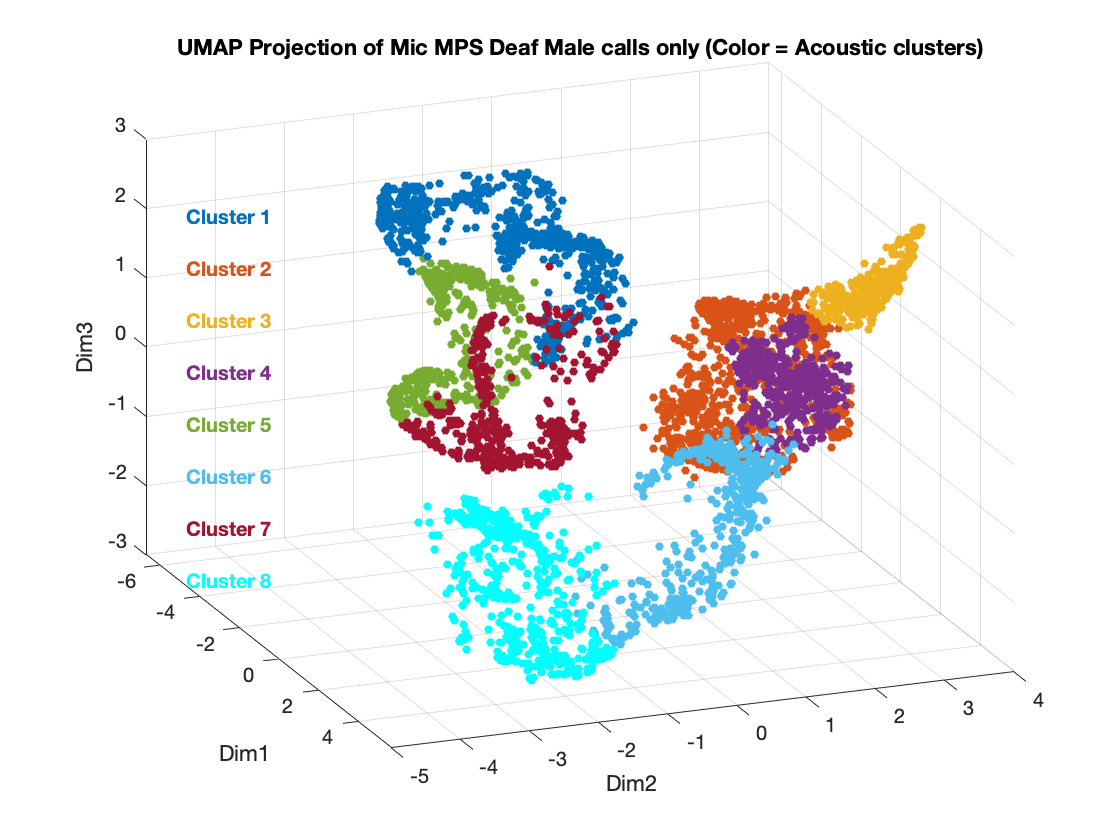

%%
figure()
scatter3(MPSmicReduction4Clustering(contains(SexDeafMic, 'DM'),1), MPSmicReduction4Clustering(contains(SexDeafMic, 'DM'),2),MPSmicReduction4Clustering(contains(SexDeafMic, 'DM'),3),20,ColorCode(TmicDMale,:,:),'filled')
xlabel('Dim1')
ylabel('Dim2')
zlabel('Dim3')
ZLim = get(gca, 'ZLim');
title('UMAP Projection of Mic MPS Deaf Male calls only (Color = Acoustic clusters)')
for gg=1:NGroups
    text(-5,-4.9, ZLim(2)-diff(ZLim)*gg/NGroups, sprintf('Cluster %d',gg), 'Color',ColorCode(gg,:), 'FontWeight','bold' )
end
view([68.50 26.52])

#### Project all calls from all female individuals irrespective of deafening status

Using UMAP projection of all bats calculate an agglomerative hierarchical cluster tree Z for males only

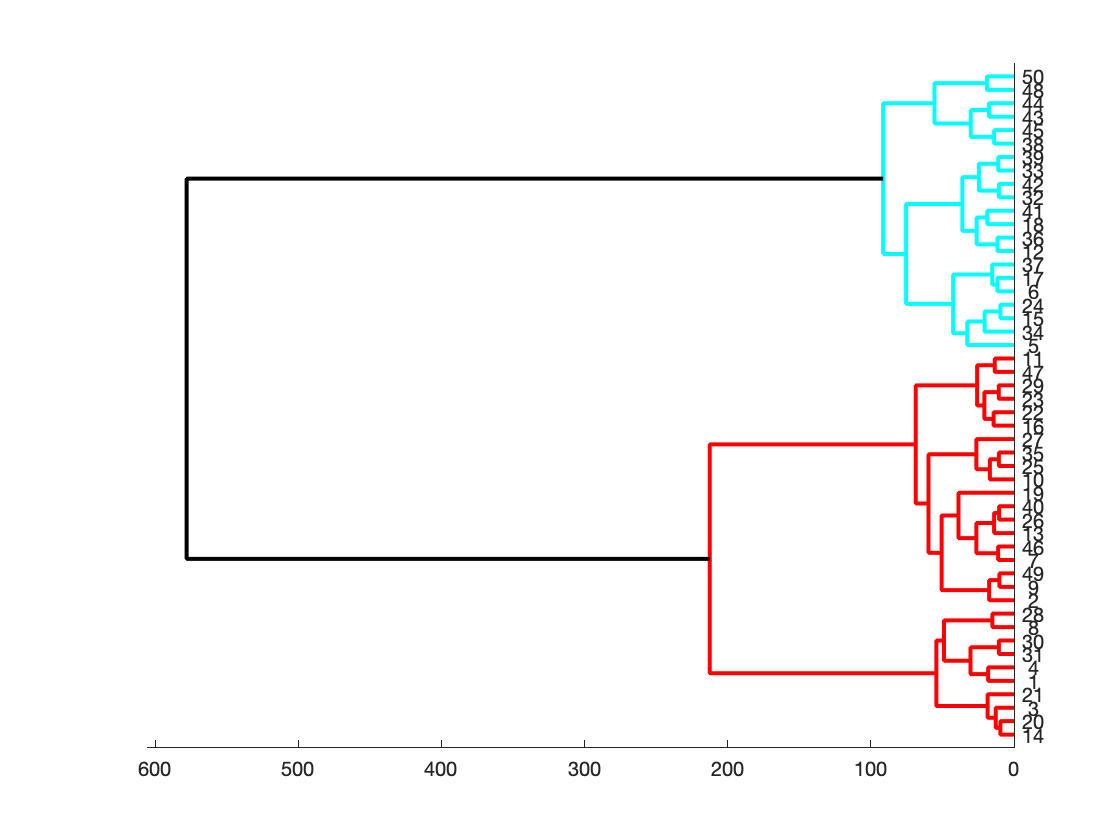

Z = linkage(MPSmicReduction4Clustering(contains(SexDeafMic, 'F'),:),'ward','euclidean');
% Cut the tree at first level and plot dendogram
[D1, T1, ~] = dendrogram(Z,50, 'ColorThreshold','Default','Orientation','left');
set(D1,'LineWidth',2)

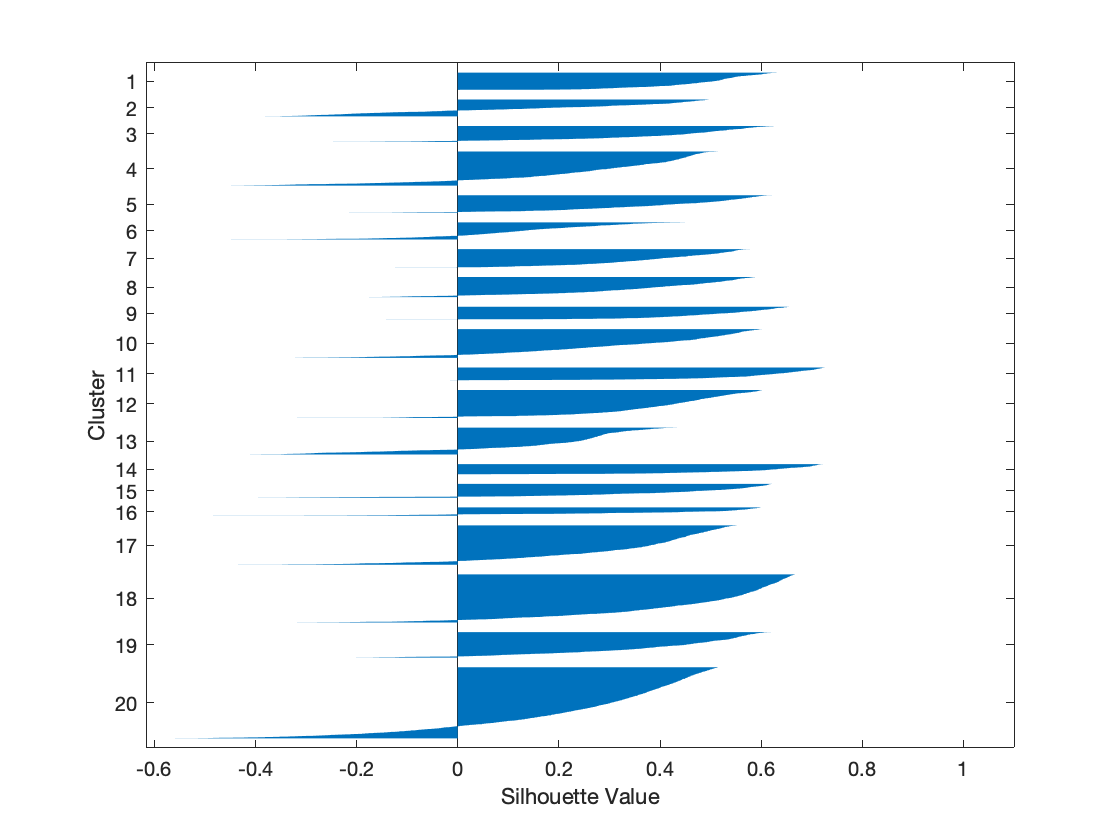

% Evaluate cluster quality accross various tree cut levels
ClustSize = 2:20;
MeanSilhouette = nan(size(ClustSize));
MedianSilhouette = nan(size(ClustSize));
PercLowSilhouette = nan(size(ClustSize));
LowSi = 0.3;
for cc=1:length(ClustSize)
    T = cluster(Z,'maxclust',ClustSize(cc));
    [Si,h] = silhouette(MPSmicReduction4Clustering(contains(SexDeafMic, 'F'),:),T, 'Euclidean');
    MeanSilhouette(cc) = mean(Si);
    MedianSilhouette(cc) = median(Si);
    PercLowSilhouette(cc) = sum(Si<LowSi)/length(Si);
end

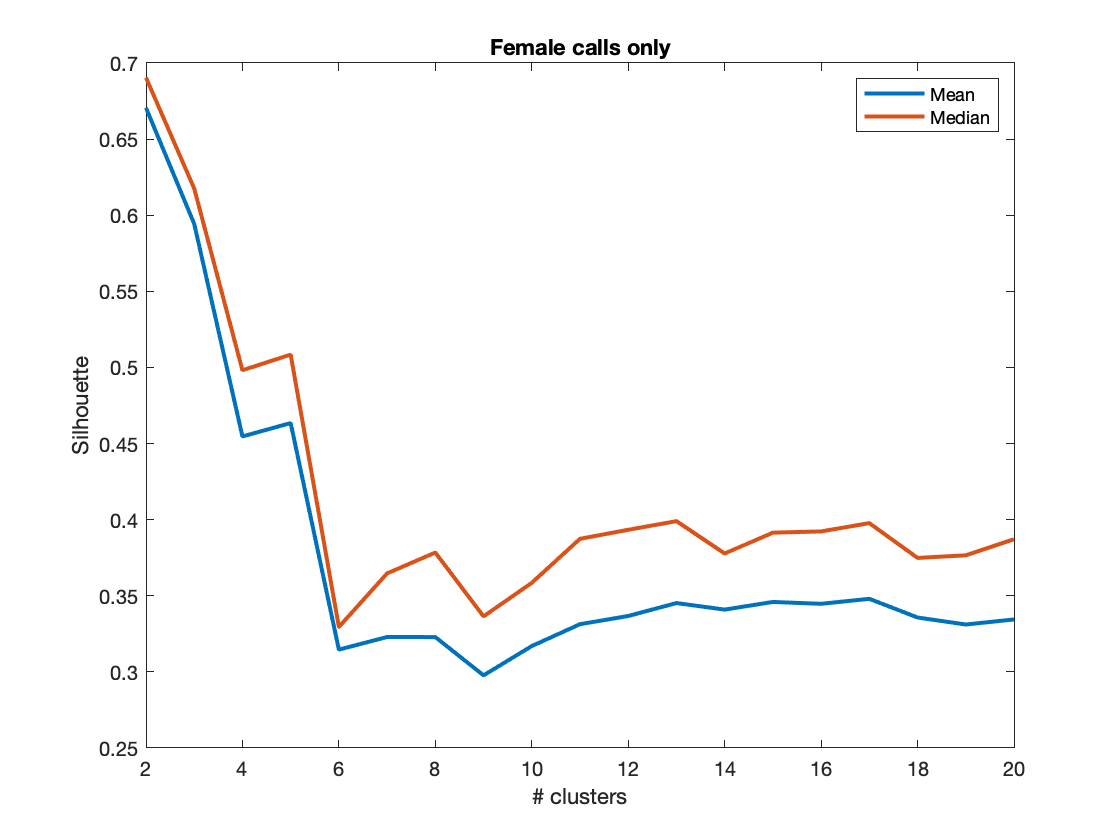

figure()
plot(2:20,MeanSilhouette, 'LineWidth',2)
hold on
plot(2:20,MedianSilhouette, 'LineWidth',2)
ylabel('Silhouette')
xlabel('# clusters')
legend('Mean', 'Median')
title('Female calls only')
hold off

eva = evalclusters(MPSmicReduction4Clustering(contains(SexDeafMic, 'F'),:), 'linkage','CalinskiHarabasz','KList',1:15)

eva =   CalinskiHarabaszEvaluation with properties:

    NumObservations: 14049
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 4.6470e+04 4.7744e+04 3.8260e+04 3.3077e+04 3.0179e+04 2.8073e+04 2.6709e+04 2.6065e+04 2.5705e+04 2.5739e+04 2.5550e+04 2.5341e+04 2.5173e+04 2.4920e+04]
           OptimalK: 3


eva = evalclusters(MPSmicReduction4Clustering(contains(SexDeafMic, 'F'),:), 'linkage','DaviesBouldin','KList',1:15)

eva =   DaviesBouldinEvaluation with properties:

    NumObservations: 14049
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 0.4839 0.5911 1.0215 0.9495 1.1490 1.1608 1.1060 1.1662 1.0989 1.0178 1.0032 0.9618 1.0174 0.9805]
           OptimalK: 2


eva = evalclusters(MPSmicReduction4Clustering(contains(SexDeafMic, 'F'),:), 'linkage','silhouette','KList',1:15)

eva =   SilhouetteEvaluation with properties:

    NumObservations: 14049
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 0.8652 0.8022 0.6344 0.6473 0.4342 0.4484 0.4415 0.4041 0.4322 0.4612 0.4688 0.4836 0.4778 0.4830]
           OptimalK: 2


Cut the Tree at 9 (NGroups) clusters and get the leaves labels (T)

NGroups = 9;
figure()
t=tiledlayout(1,2);
CTinCluster = nan(NGroups,length(UCT));
nexttile
[D, TmicFemale, ~] = dendrogram(Z,NGroups, 'ColorThreshold','Default','Orientation','left');
set(D,'LineWidth',2)
CallTypeMicAudioGood = CallType(MicAudioGood01);
CallTypeMicAudioGoodM = CallTypeMicAudioGood(contains(SexDeafMic, 'F'))

CallTypeMicAudioGoodM = 14049×1 cell array
    {'BB'}
    {'Ch'}
    {'Sq'}
    {'Sq'}
    {'Sq'}
    {'Pi'}
    {'Bu'}
    {'Bu'}
    {'BB'}
    {'Bu'}
    {'Bu'}
    {'Bu'}
    {'Bu'}
    {'Bu'}
    {'Bu'}
    {'Bu'}
    {'Bu'}
    {'Bu'}
    {'Bu'}
    {'Bu'}
    {'Bu'}
    {'BB'}
    {'Bu'}
    {'BB'}
    {'Bu'}
    {'Bu'}
    {'Bu'}
    {'LT'}
    {'Sq'}
    {'Sq'}


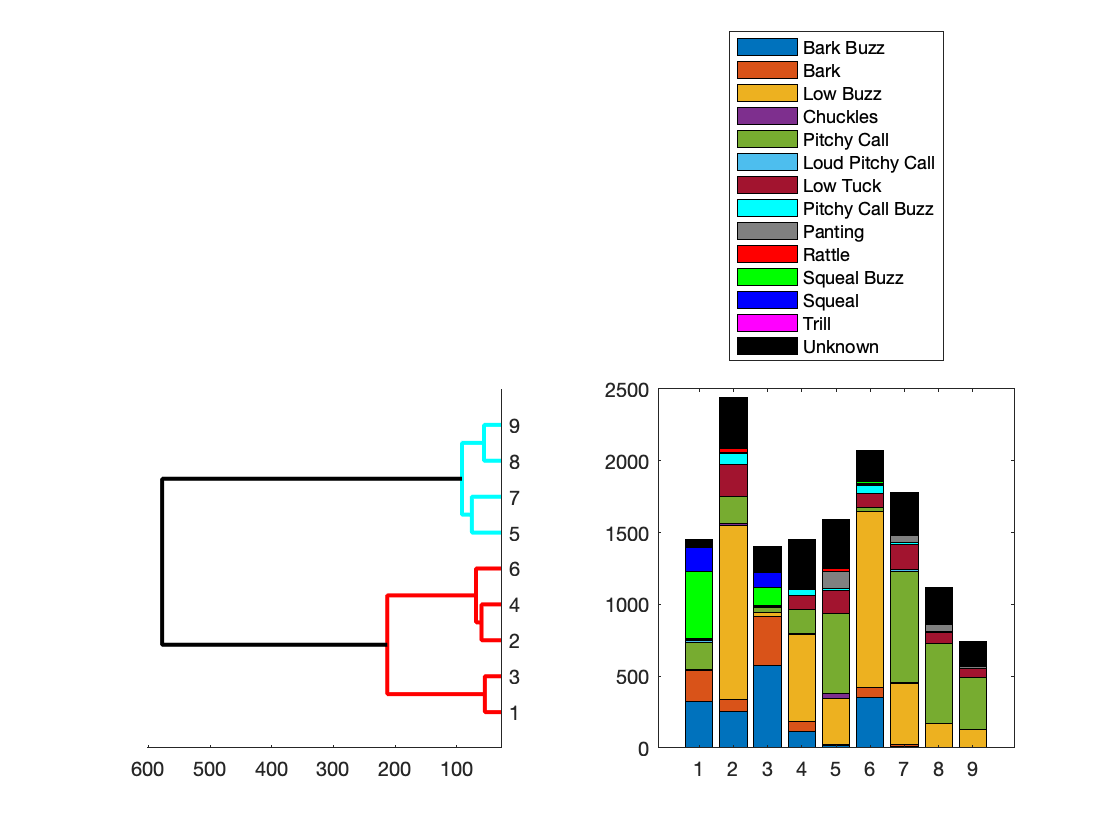

for cc=1:NGroups
    for ct=1:length(UCT)
        CTinCluster(cc,ct) = sum(strcmp(CallTypeMicAudioGoodM(TmicFemale==cc), UCT{ct}));
    end
end
nexttile
B = bar(CTinCluster, 'stacked');
B(8).FaceColor = ColorCode(8,:);
B(9).FaceColor = ColorCode(9,:);
B(10).FaceColor = ColorCode(10,:);
B(11).FaceColor = ColorCode(11,:);
B(12).FaceColor = ColorCode(12,:);
B(13).FaceColor = ColorCode(13,:);
B(14).FaceColor = ColorCode(14,:);
legend(UCTFull, 'Location', 'northoutside')

Project the vocalizations in 3D UMAP space and colorcode according to acoustic hierarchical agglomerative clusters.

%%
figure()
scatter3(MPSmicReduction4Clustering(contains(SexDeafMic, 'F'),1), MPSmicReduction4Clustering(contains(SexDeafMic, 'F'),2),MPSmicReduction4Clustering(contains(SexDeafMic, 'F'),3),20,ColorCode(TmicFemale,:,:),'filled')
xlabel('Dim1')
ylabel('Dim2')
zlabel('Dim3')
ZLim = get(gca, 'ZLim');
title('UMAP Projection of Mic MPS Female calls only (Color = Acoustic clusters)')
for gg=1:NGroups
    text(-5,-4.9, ZLim(2)-diff(ZLim)*gg/NGroups, sprintf('Cluster %d',gg), 'Color',ColorCode(gg,:), 'FontWeight','bold' )
end
view([68.50 26.52])

#### Project all calls from all hearing female individuals

Using UMAP projection of all bats calculate an agglomerative hierarchical cluster tree Z for females only

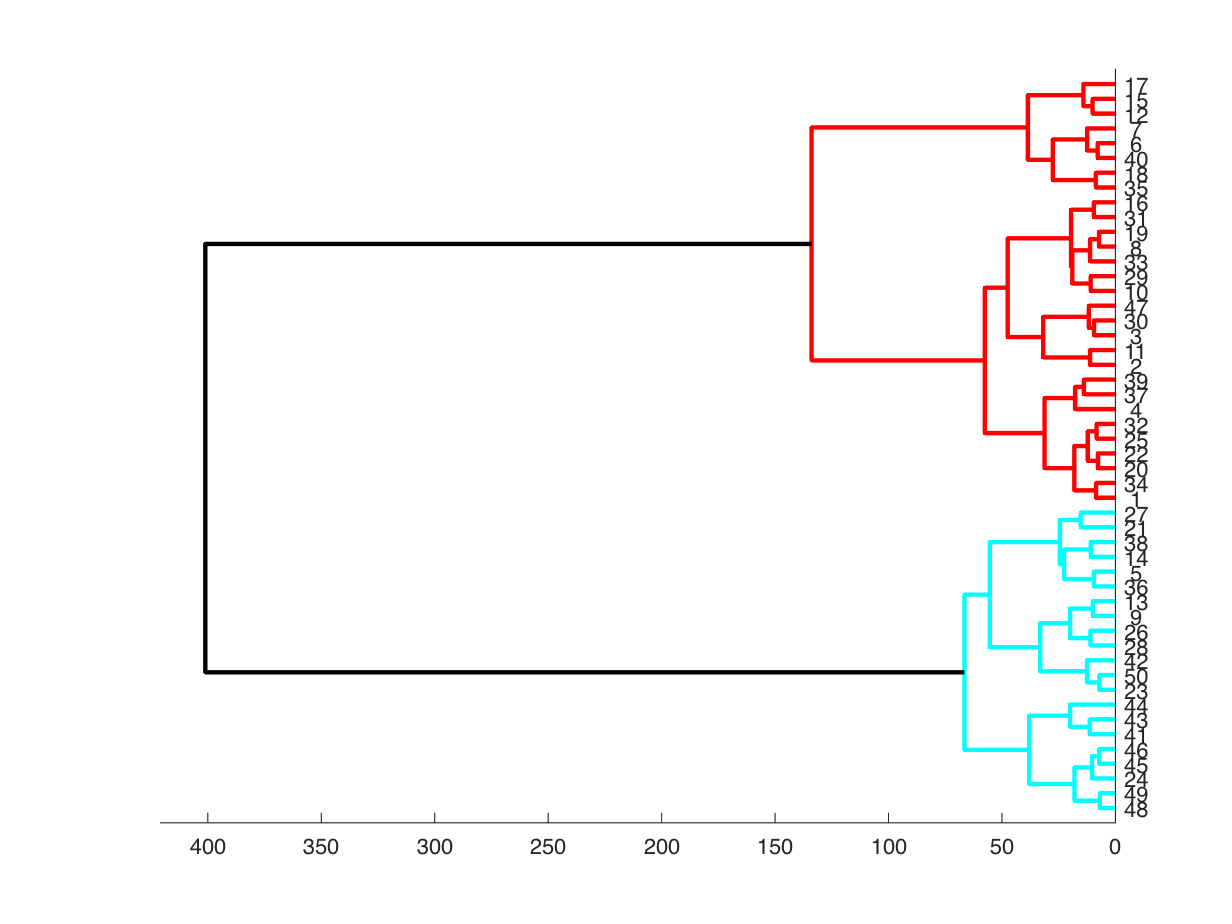

Z = linkage(MPSmicReduction4Clustering(contains(SexDeafMic, 'HF'),:),'ward','euclidean');
% Cut the tree at first level and plot dendogram
[D1, T1, ~] = dendrogram(Z,50, 'ColorThreshold','Default','Orientation','left');
set(D1,'LineWidth',2)

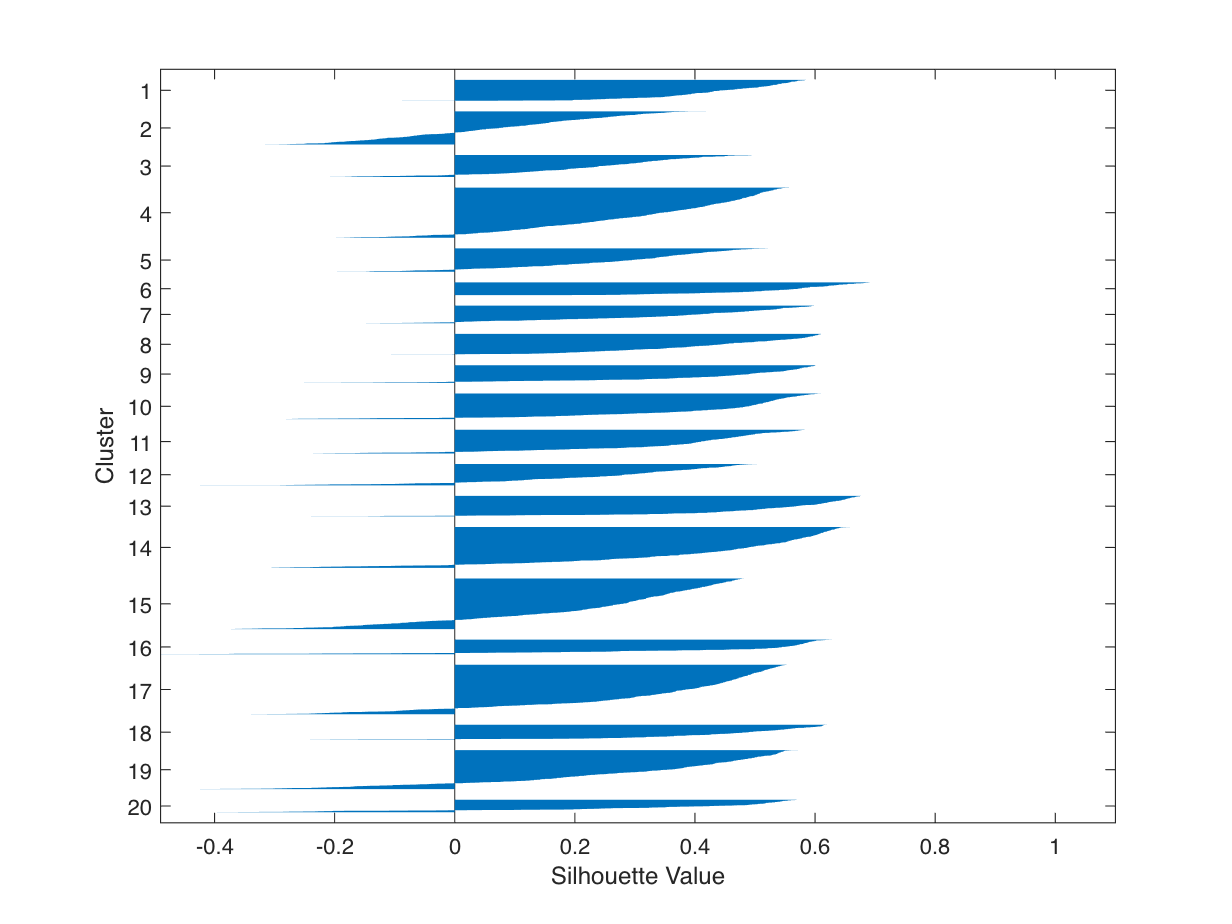

% Evaluate cluster quality accross various tree cut levels
ClustSize = 2:20;
MeanSilhouette = nan(size(ClustSize));
MedianSilhouette = nan(size(ClustSize));
PercLowSilhouette = nan(size(ClustSize));
LowSi = 0.3;
for cc=1:length(ClustSize)
    T = cluster(Z,'maxclust',ClustSize(cc));
    [Si,h] = silhouette(MPSmicReduction4Clustering(contains(SexDeafMic, 'HF'),:),T, 'Euclidean');
    MeanSilhouette(cc) = mean(Si);
    MedianSilhouette(cc) = median(Si);
    PercLowSilhouette(cc) = sum(Si<LowSi)/length(Si);
end

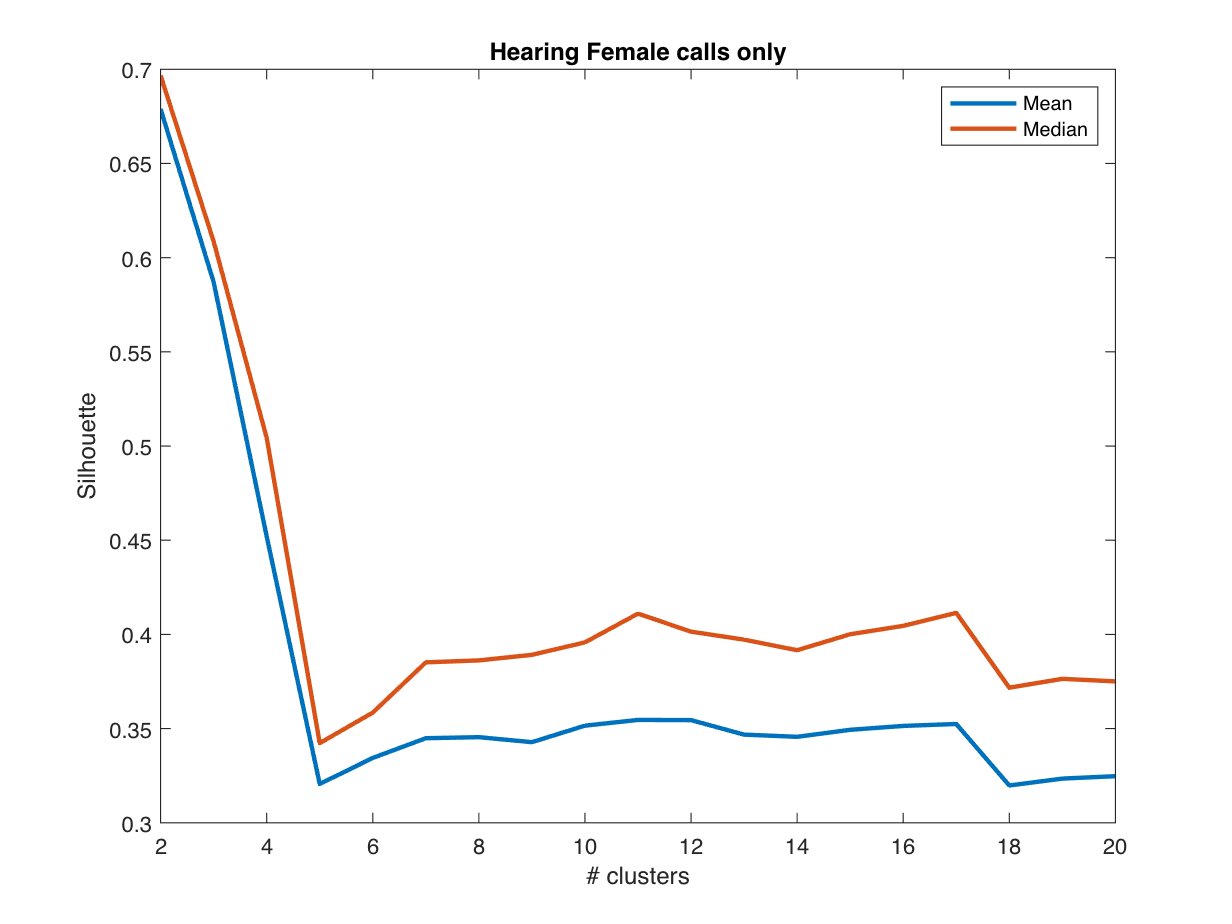

figure()
plot(2:20,MeanSilhouette, 'LineWidth',2)
hold on
plot(2:20,MedianSilhouette, 'LineWidth',2)
ylabel('Silhouette')
xlabel('# clusters')
legend('Mean', 'Median')
title('Hearing Female calls only')
hold off

eva = evalclusters(MPSmicReduction4Clustering(contains(SexDeafMic, 'HF'),:), 'linkage','CalinskiHarabasz','KList',1:15)

eva =   CalinskiHarabaszEvaluation with properties:

    NumObservations: 7541
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 2.5651e+04 2.2956e+04 1.8466e+04 1.6260e+04 1.5400e+04 1.4778e+04 1.4044e+04 1.3715e+04 1.3354e+04 1.3165e+04 1.3167e+04 1.3081e+04 1.2922e+04 1.2759e+04]
           OptimalK: 2


eva = evalclusters(MPSmicReduction4Clustering(contains(SexDeafMic, 'HF'),:), 'linkage','DaviesBouldin','KList',1:15)

eva =   DaviesBouldinEvaluation with properties:

    NumObservations: 7541
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 0.4737 0.6054 1.0111 1.2257 1.1282 1.0520 1.0445 1.0277 0.9975 0.9402 0.9738 0.9487 0.9801 0.9619]
           OptimalK: 2


eva = evalclusters(MPSmicReduction4Clustering(contains(SexDeafMic, 'HF'),:), 'linkage','silhouette','KList',1:15)

eva =   SilhouetteEvaluation with properties:

    NumObservations: 7541
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 0.8734 0.7958 0.6328 0.4544 0.4742 0.4879 0.4933 0.4853 0.4996 0.4985 0.5027 0.4906 0.4891 0.4928]
           OptimalK: 2


Cut the Tree at 5 (NGroups) clusters and get the leaves labels (T)

NGroups = 5;
figure()
t=tiledlayout(1,2);
CTinCluster = nan(NGroups,length(UCT));
nexttile
[D, TmicHFemale, ~] = dendrogram(Z,NGroups, 'ColorThreshold','Default','Orientation','left');
set(D,'LineWidth',2)
CallTypeMicAudioGood = CallType(MicAudioGood01);
CallTypeMicAudioGoodF = CallTypeMicAudioGood(contains(SexDeafMic, 'HF'))

CallTypeMicAudioGoodF = 7541×1 cell array
    {'Bu'}
    {'Bu'}
    {'BB'}
    {'Bu'}
    {'Bu'}
    {'Bu'}
    {'Bu'}
    {'Bu'}
    {'Bu'}
    {'Bu'}
    {'Bu'}
    {'Bu'}
    {'Bu'}
    {'Bu'}
    {'Bu'}
    {'BB'}
    {'Bu'}
    {'BB'}
    {'Bu'}
    {'Bu'}
    {'Bu'}
    {'LT'}
    {'Pa'}
    {'Pa'}
    {'Pa'}
    {'Pa'}
    {'Pa'}
    {'Pa'}
    {'BB'}
    {'BB'}


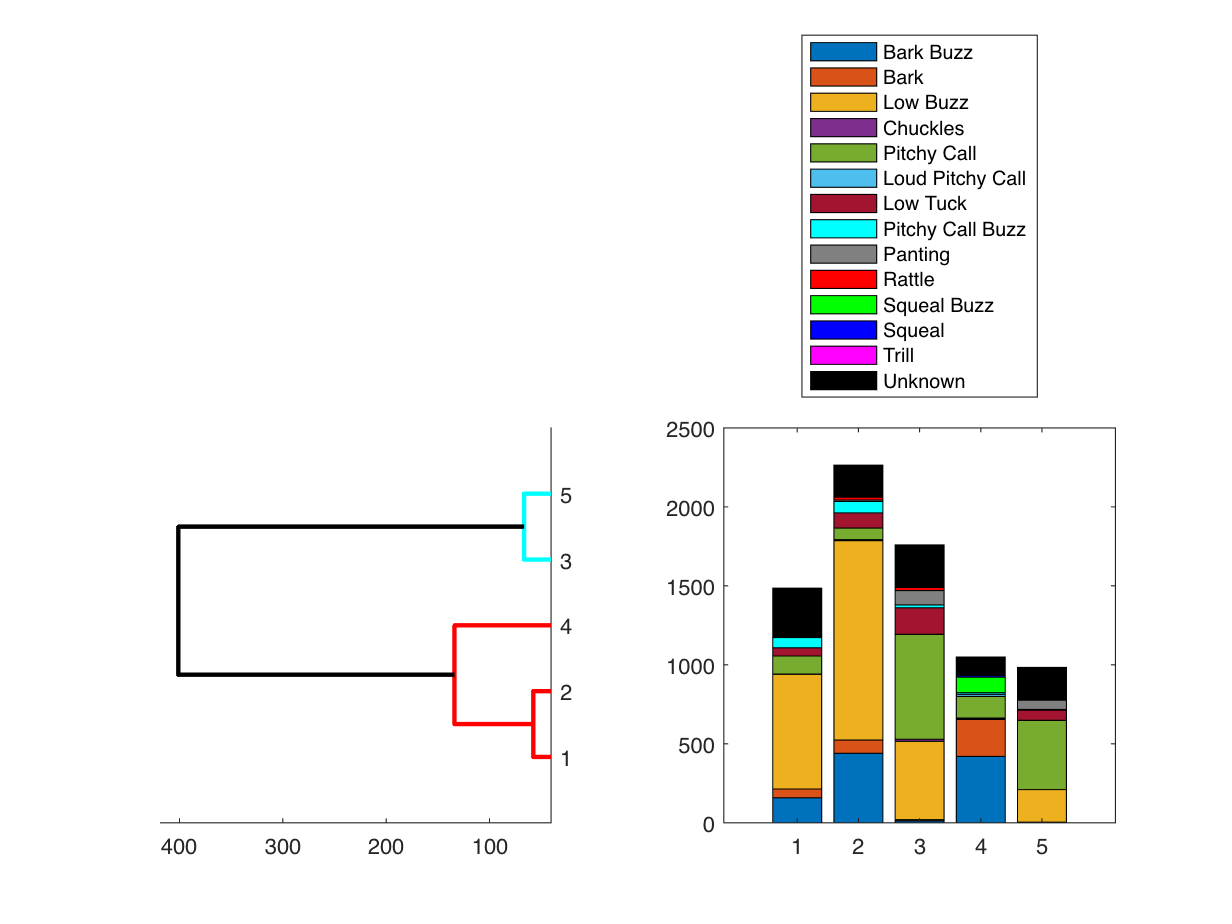

for cc=1:NGroups
    for ct=1:length(UCT)
        CTinCluster(cc,ct) = sum(strcmp(CallTypeMicAudioGoodF(TmicHFemale==cc), UCT{ct}));
    end
end
nexttile
B = bar(CTinCluster, 'stacked');
B(8).FaceColor = ColorCode(8,:);
B(9).FaceColor = ColorCode(9,:);
B(10).FaceColor = ColorCode(10,:);
B(11).FaceColor = ColorCode(11,:);
B(12).FaceColor = ColorCode(12,:);
B(13).FaceColor = ColorCode(13,:);
B(14).FaceColor = ColorCode(14,:);
legend(UCTFull, 'Location', 'northoutside')

Project the vocalizations in 3D UMAP space and colorcode according to acoustic hierarchical agglomerative clusters.

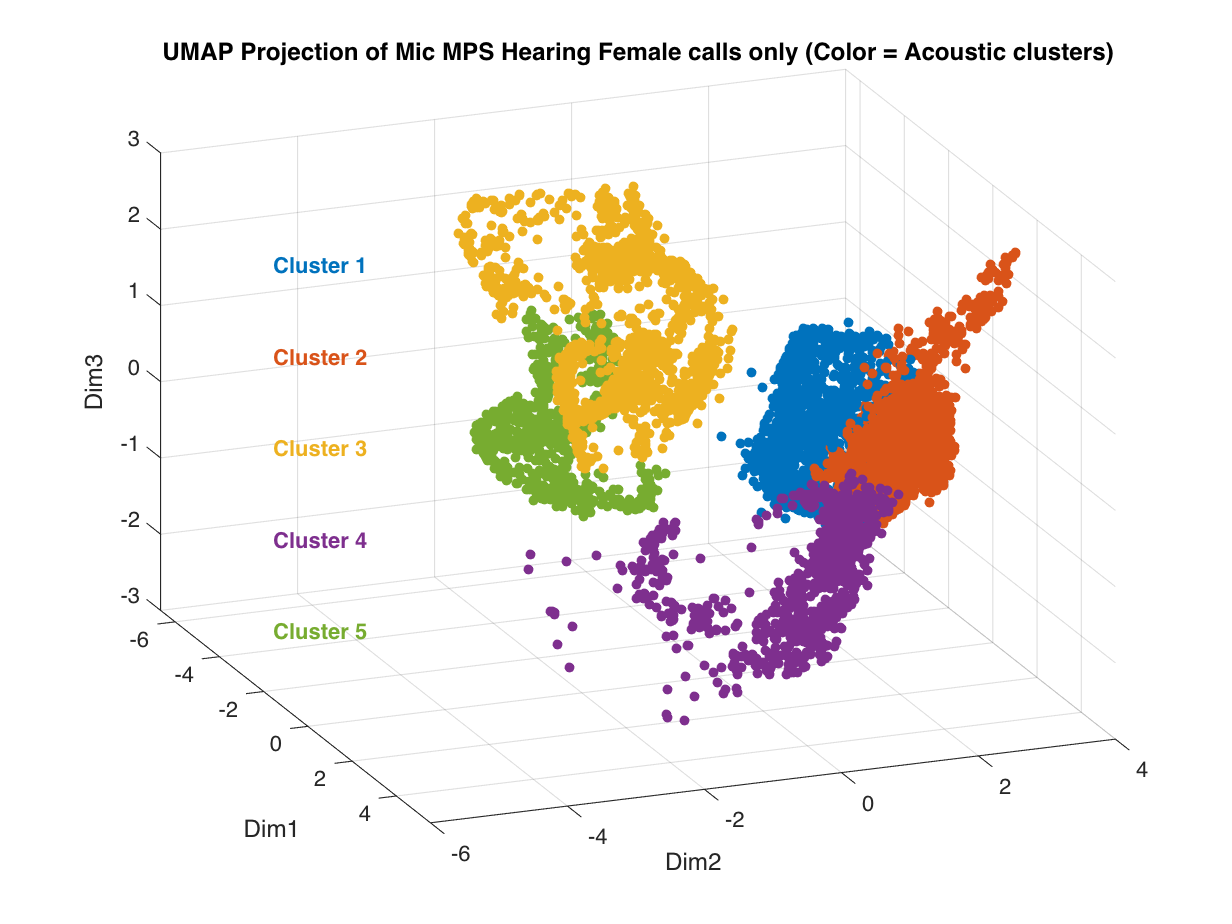

%%
figure()
scatter3(MPSmicReduction4Clustering(contains(SexDeafMic, 'HF'),1), MPSmicReduction4Clustering(contains(SexDeafMic, 'HF'),2),MPSmicReduction4Clustering(contains(SexDeafMic, 'HF'),3),20,ColorCode(TmicHFemale,:,:),'filled')
xlabel('Dim1')
ylabel('Dim2')
zlabel('Dim3')
ZLim = get(gca, 'ZLim');
title('UMAP Projection of Mic MPS Hearing Female calls only (Color = Acoustic clusters)')
for gg=1:NGroups
    text(-5,-4.9, ZLim(2)-diff(ZLim)*gg/NGroups, sprintf('Cluster %d',gg), 'Color',ColorCode(gg,:), 'FontWeight','bold' )
end
view([68.50 26.52])

#### Project all calls from all deaf female individuals

Using UMAP projection of all bats calculate an agglomerative hierarchical cluster tree Z for females only

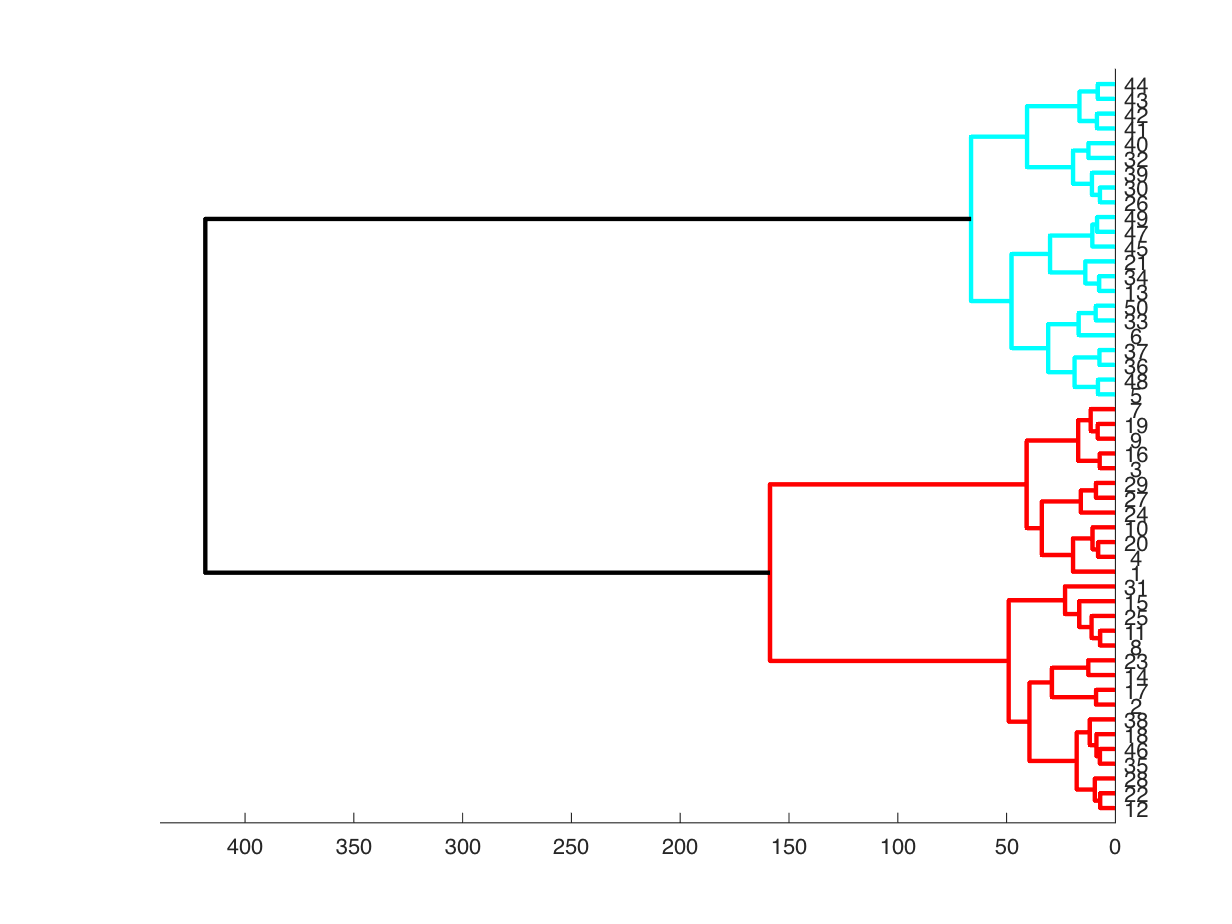

Z = linkage(MPSmicReduction4Clustering(contains(SexDeafMic, 'DF'),:),'ward','euclidean');
% Cut the tree at first level and plot dendogram
[D1, T1, ~] = dendrogram(Z,50, 'ColorThreshold','Default','Orientation','left');
set(D1,'LineWidth',2)

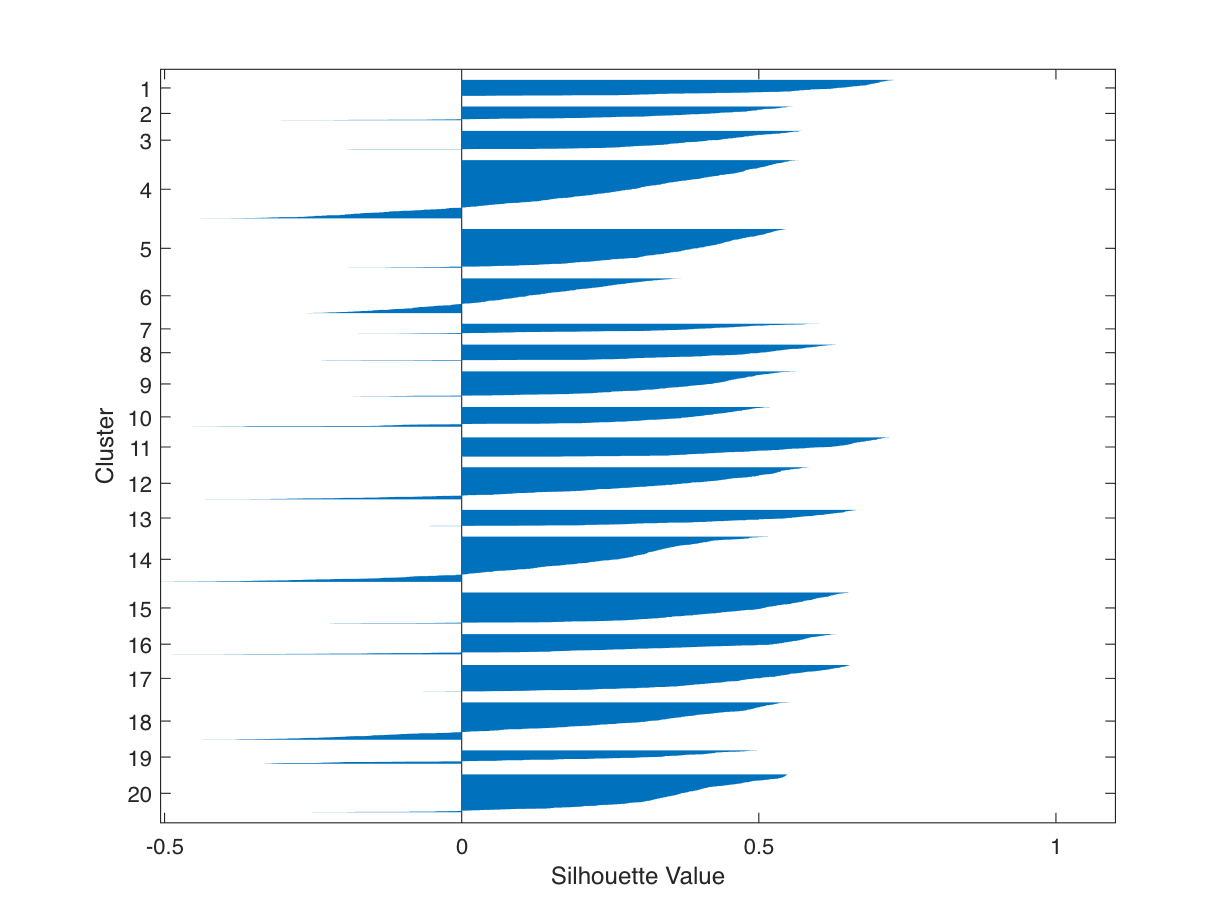

% Evaluate cluster quality accross various tree cut levels
ClustSize = 2:20;
MeanSilhouette = nan(size(ClustSize));
MedianSilhouette = nan(size(ClustSize));
PercLowSilhouette = nan(size(ClustSize));
LowSi = 0.3;
for cc=1:length(ClustSize)
    T = cluster(Z,'maxclust',ClustSize(cc));
    [Si,h] = silhouette(MPSmicReduction4Clustering(contains(SexDeafMic, 'DF'),:),T, 'Euclidean');
    MeanSilhouette(cc) = mean(Si);
    MedianSilhouette(cc) = median(Si);
    PercLowSilhouette(cc) = sum(Si<LowSi)/length(Si);
end

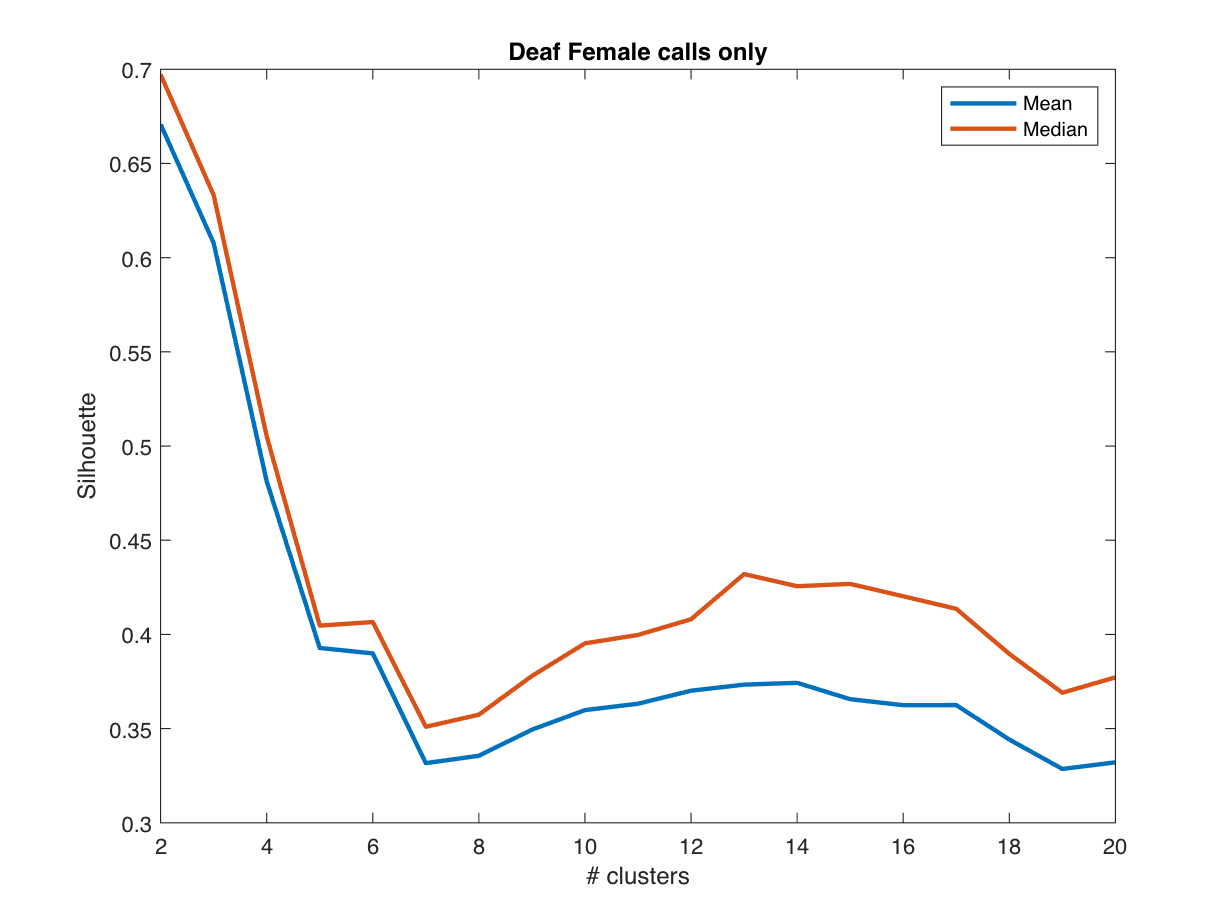

figure()
plot(2:20,MeanSilhouette, 'LineWidth',2)
hold on
plot(2:20,MedianSilhouette, 'LineWidth',2)
ylabel('Silhouette')
xlabel('# clusters')
legend('Mean', 'Median')
title('Deaf Female calls only')
hold off

eva = evalclusters(MPSmicReduction4Clustering(contains(SexDeafMic, 'DF'),:), 'linkage','CalinskiHarabasz','KList',1:15)

eva =   CalinskiHarabaszEvaluation with properties:

    NumObservations: 6508
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 2.2242e+04 2.5063e+04 2.0556e+04 1.7554e+04 1.6113e+04 1.5012e+04 1.4541e+04 1.4478e+04 1.4298e+04 1.4168e+04 1.4224e+04 1.4455e+04 1.4313e+04 1.4008e+04]
           OptimalK: 3


eva = evalclusters(MPSmicReduction4Clustering(contains(SexDeafMic, 'DF'),:), 'linkage','DaviesBouldin','KList',1:15)

eva =   DaviesBouldinEvaluation with properties:

    NumObservations: 6508
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 0.4805 0.5719 0.9683 1.1502 1.0988 1.1876 1.1418 1.1154 1.0372 1.0054 0.9749 0.9122 0.9015 0.8856]
           OptimalK: 2


eva = evalclusters(MPSmicReduction4Clustering(contains(SexDeafMic, 'DF'),:), 'linkage','silhouette','KList',1:15)

eva =   SilhouetteEvaluation with properties:

    NumObservations: 6508
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 0.8620 0.8131 0.6653 0.5468 0.5404 0.4605 0.4626 0.4832 0.5076 0.5131 0.5220 0.5225 0.5248 0.5065]
           OptimalK: 2


Cut the Tree at 7 (NGroups) clusters and get the leaves labels (T)

NGroups = 7;
figure()
t=tiledlayout(1,2);
CTinCluster = nan(NGroups,length(UCT));
nexttile
[D, TmicDFemale, ~] = dendrogram(Z,NGroups, 'ColorThreshold','Default','Orientation','left');
set(D,'LineWidth',2)
CallTypeMicAudioGood = CallType(MicAudioGood01);
CallTypeMicAudioGoodF = CallTypeMicAudioGood(contains(SexDeafMic, 'DF'))

CallTypeMicAudioGoodF = 6508×1 cell array
    {'BB'}
    {'Ch'}
    {'Sq'}
    {'Sq'}
    {'Sq'}
    {'Pi'}
    {'LT'}
    {'Sq'}
    {'Sq'}
    {'Sq'}
    {'Sq'}
    {'Pi'}
    {'Pi'}
    {'Bu'}
    {'Bu'}
    {'Sq'}
    {'BB'}
    {'Ra'}
    {'Sq'}
    {'Sq'}
    {'Sq'}
    {'Sq'}
    {'Bu'}
    {'Pi'}
    {'Sq'}
    {'Sq'}
    {'Pi'}
    {'Bu'}
    {'BB'}
    {'BB'}


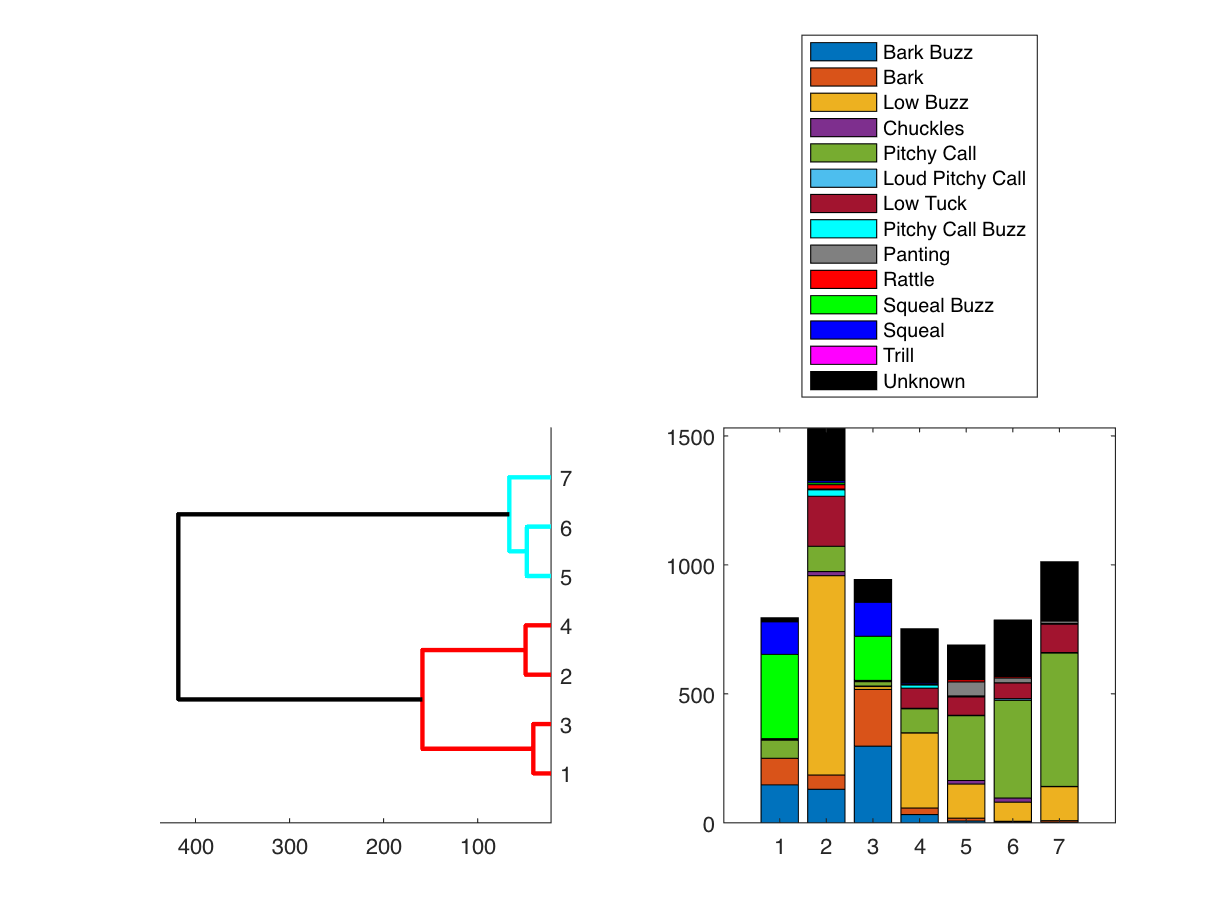

for cc=1:NGroups
    for ct=1:length(UCT)
        CTinCluster(cc,ct) = sum(strcmp(CallTypeMicAudioGoodF(TmicDFemale==cc), UCT{ct}));
    end
end
nexttile
B = bar(CTinCluster, 'stacked');
B(8).FaceColor = ColorCode(8,:);
B(9).FaceColor = ColorCode(9,:);
B(10).FaceColor = ColorCode(10,:);
B(11).FaceColor = ColorCode(11,:);
B(12).FaceColor = ColorCode(12,:);
B(13).FaceColor = ColorCode(13,:);
B(14).FaceColor = ColorCode(14,:);
legend(UCTFull, 'Location', 'northoutside')

Project the vocalizations in 3D UMAP space and colorcode according to acoustic hierarchical agglomerative clusters.

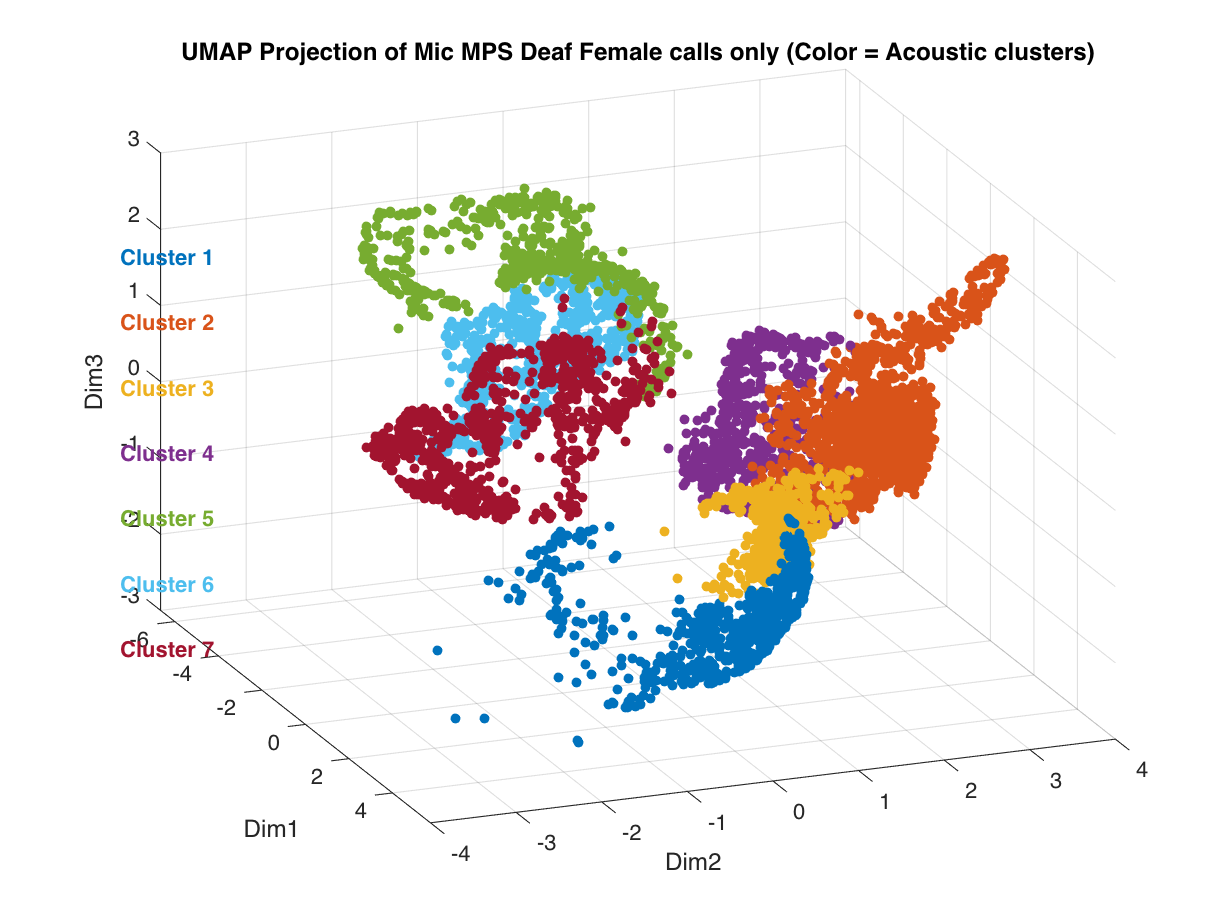

%%
figure()
scatter3(MPSmicReduction4Clustering(contains(SexDeafMic, 'DF'),1), MPSmicReduction4Clustering(contains(SexDeafMic, 'DF'),2),MPSmicReduction4Clustering(contains(SexDeafMic, 'DF'),3),20,ColorCode(TmicDFemale,:,:),'filled')
xlabel('Dim1')
ylabel('Dim2')
zlabel('Dim3')
ZLim = get(gca, 'ZLim');
title('UMAP Projection of Mic MPS Deaf Female calls only (Color = Acoustic clusters)')
for gg=1:NGroups
    text(-5,-4.9, ZLim(2)-diff(ZLim)*gg/NGroups, sprintf('Cluster %d',gg), 'Color',ColorCode(gg,:), 'FontWeight','bold' )
end
view([68.50 26.52])